# EE557 HW6

Qingchuan Hou

11/21/2022

## Classical PI

clear
clc

syms i_ast i v_ast v omega e
syms s K_p K_i K_v L_p R_p K_e K_hat_e b_p T_L J T_em K_t


% Classical PI System
eq1_1 = v_ast == K_p*(i_ast-i) + (1/s)*K_i*(i_ast-i) + omega*K_hat_e

$$eq1\_1 = v^{*}={\hat{K}}_{e}\,\omega -K_{p}\,\left(i-i^{*}\right)-\frac{K_{i}\,\left(i-i^{*}\right)}{s}$$

eq1_2 = v == K_v * v_ast 

$$eq1\_2 = v=K_{v}\,v^{*}$$

eq1_3 = i == (v-e-i*R_p) * (1/L_p) * (1/s)

$$eq1\_3 = i=-\frac{e-v+R_{p}\,i}{L_{p}\,s}$$

eq1_4 = e == omega*K_e

$$eq1\_4 = e=K_{e}\,\omega$$

eq1_5 = T_em == i * K_t

$$eq1\_5 = T_{\mathrm{em}}=K_{t}\,i$$

eq1_6 = omega == (1/J) * (1/s) * (T_em - T_L - omega*b_p)

$$eq1\_6 = \omega =-\frac{T_{L}-T_{\mathrm{em}}+b_{p}\,\omega }{J\,s}$$


eqs1 = [eq1_1, eq1_2, eq1_3, eq1_4, eq1_5, eq1_6];

% Current Regulator Command Tracking TF
S = solve(eqs1, [i omega v_ast v T_em e]);
EQ1_1 = i == collect(S.i, [i_ast,T_L])

$$EQ1\_1 = \begin{array}{l} i=\frac{K_{i}\,K_{v}\,b_{p}+J\,K_{p}\,K_{v}\,s^{2}+J\,K_{i}\,K_{v}\,s+K_{p}\,K_{v}\,b_{p}\,s}{\sigma_{1}}\,i^{*}+\frac{K_{e}\,s-{\hat{K}}_{e}\,K_{v}\,s}{\sigma_{1}}\,T_{L}\\ \mathrm{where}\\ \sigma_{1}=K_{i}\,K_{v}\,b_{p}+K_{e}\,K_{t}\,s+R_{p}\,b_{p}\,s+J\,L_{p}\,s^{3}+J\,R_{p}\,s^{2}+L_{p}\,b_{p}\,s^{2}+J\,K_{p}\,K_{v}\,s^{2}+J\,K_{i}\,K_{v}\,s-{\hat{K}}_{e}\,K_{t}\,K_{v}\,s+K_{p}\,K_{v}\,b_{p}\,s \end{array}$$


subtheta1_1 = children(rhs(EQ1_1));
EQ1_2 = i/i_ast == subtheta1_1{1}/i_ast

$$EQ1\_2 = \begin{array}{l} \frac{i}{i^{*}}=\frac{K_{i}\,K_{v}\,b_{p}+\sigma_{1}+J\,K_{i}\,K_{v}\,s+K_{p}\,K_{v}\,b_{p}\,s}{K_{i}\,K_{v}\,b_{p}+K_{e}\,K_{t}\,s+R_{p}\,b_{p}\,s+J\,L_{p}\,s^{3}+J\,R_{p}\,s^{2}+L_{p}\,b_{p}\,s^{2}+\sigma_{1}+J\,K_{i}\,K_{v}\,s-{\hat{K}}_{e}\,K_{t}\,K_{v}\,s+K_{p}\,K_{v}\,b_{p}\,s}\\ \mathrm{where}\\ \sigma_{1}=J\,K_{p}\,K_{v}\,s^{2} \end{array}$$

## Active Resistance

syms R_hat_p R_a

% Active Resistance System
eq2_1 = v_ast == R_a*(i_ast-i) + omega*K_hat_e + i*R_hat_p

$$eq2\_1 = v^{*}={\hat{K}}_{e}\,\omega +{\hat{R}}_{p}\,i-R_{a}\,\left(i-i^{*}\right)$$

eq2_2 = v == K_v * v_ast 

$$eq2\_2 = v=K_{v}\,v^{*}$$

eq2_3 = i == (v-e-i*R_p) * (1/L_p) * (1/s)

$$eq2\_3 = i=-\frac{e-v+R_{p}\,i}{L_{p}\,s}$$

eq2_4 = e == omega*K_e

$$eq2\_4 = e=K_{e}\,\omega$$

eq2_5 = T_em == i * K_t

$$eq2\_5 = T_{\mathrm{em}}=K_{t}\,i$$

eq2_6 = omega == (1/J) * (1/s) * (T_em - T_L - omega*b_p)

$$eq2\_6 = \omega =-\frac{T_{L}-T_{\mathrm{em}}+b_{p}\,\omega }{J\,s}$$


eqs2 = [eq2_1, eq2_2, eq2_3, eq2_4, eq2_5, eq2_6];

% Current Regulator Command Tracking TF
S = solve(eqs2, [i omega v_ast v T_em e]);
EQ2_1 = i == collect(S.i, [i_ast,T_L])

$$EQ2\_1 = \begin{array}{l} i=\frac{K_{v}\,R_{a}\,b_{p}+J\,K_{v}\,R_{a}\,s}{\sigma_{1}}\,i^{*}+\frac{K_{e}-{\hat{K}}_{e}\,K_{v}}{\sigma_{1}}\,T_{L}\\ \mathrm{where}\\ \sigma_{1}=R_{p}\,b_{p}+K_{e}\,K_{t}-{\hat{K}}_{e}\,K_{t}\,K_{v}+K_{v}\,R_{a}\,b_{p}-K_{v}\,{\hat{R}}_{p}\,b_{p}+J\,R_{p}\,s+L_{p}\,b_{p}\,s+J\,L_{p}\,s^{2}+J\,K_{v}\,R_{a}\,s-J\,K_{v}\,{\hat{R}}_{p}\,s \end{array}$$


subtheta2_1 = children(rhs(EQ2_1));
EQ2_2 = i/i_ast == subtheta2_1{1}/i_ast

$$EQ2\_2 = \frac{i}{i^{*}}=\frac{K_{v}\,R_{a}\,b_{p}+J\,K_{v}\,R_{a}\,s}{R_{p}\,b_{p}+K_{e}\,K_{t}-{\hat{K}}_{e}\,K_{t}\,K_{v}+K_{v}\,R_{a}\,b_{p}-K_{v}\,{\hat{R}}_{p}\,b_{p}+J\,R_{p}\,s+L_{p}\,b_{p}\,s+J\,L_{p}\,s^{2}+J\,K_{v}\,R_{a}\,s-J\,K_{v}\,{\hat{R}}_{p}\,s}$$

## c1. Frequency Response of Current Regulator - Classical PI

J = 1e-5

J = 1.0000e-05

b_p = 1e-5

b_p = 1.0000e-05

K_t = 0.2

K_t = 0.2000

K_e = 0.2

K_e = 0.2000

L_p = 1e-3

L_p = 1.0000e-03

R_p = 1

R_p = 1


K_v = 1

K_v = 1


f_desired = 1000

f_desired = 1000


% With perfect decoupling
K_i = 2*pi*f_desired*R_p

K_i = 6.2832e+03

K_p = 2*pi*f_desired*L_p

K_p = 6.2832


opts = bodeoptions;
opts.FreqUnits = 'Hz';
opts.Grid = 'on';
opts.XLimMode = 'manual';
opts.XLim = [0.1,1e+4];

% zero speed
K_e = 0;
K_hat_e = 0;
EQ1_tf = subs(EQ1_2)

$$EQ1\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi \,s^{2}}{50000}+\frac{1001\,\pi \,s}{50000}+\frac{\pi }{50}}{\frac{s}{100000}+\frac{\pi }{50}+\frac{1001\,\pi \,s}{50000}+\frac{\pi \,s^{2}}{50000}+\frac{1001\,s^{2}}{100000000}+\frac{s^{3}}{100000000}}$$

tf = syms2tf(simplify(rhs(EQ1_tf)))

tf =
 
    6283
  --------
  s + 6283
 
Continuous-time transfer function.



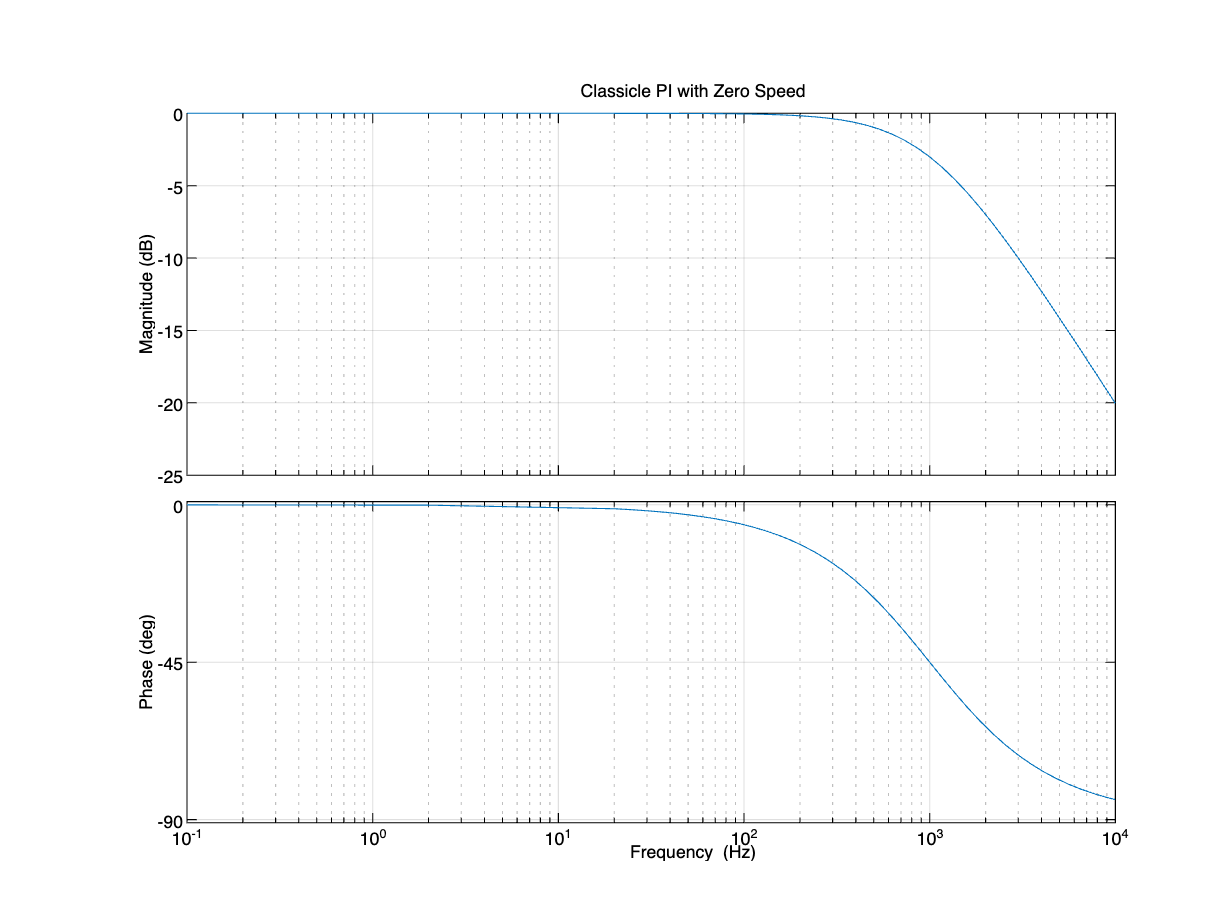


figure
bodeplot(tf,opts)
title('Classicle PI with Zero Speed')

$$EQ1\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi \,s^{2}}{50000}+\frac{1001\,\pi \,s}{50000}+\frac{\pi }{50}}{\frac{s}{100000}+\frac{\pi }{50}+\frac{1001\,\pi \,s}{50000}+\frac{\pi \,s^{2}}{50000}+\frac{1001\,s^{2}}{100000000}+\frac{s^{3}}{100000000}}$$

tf =
 
    6283
  --------
  s + 6283
 
Continuous-time transfer function.



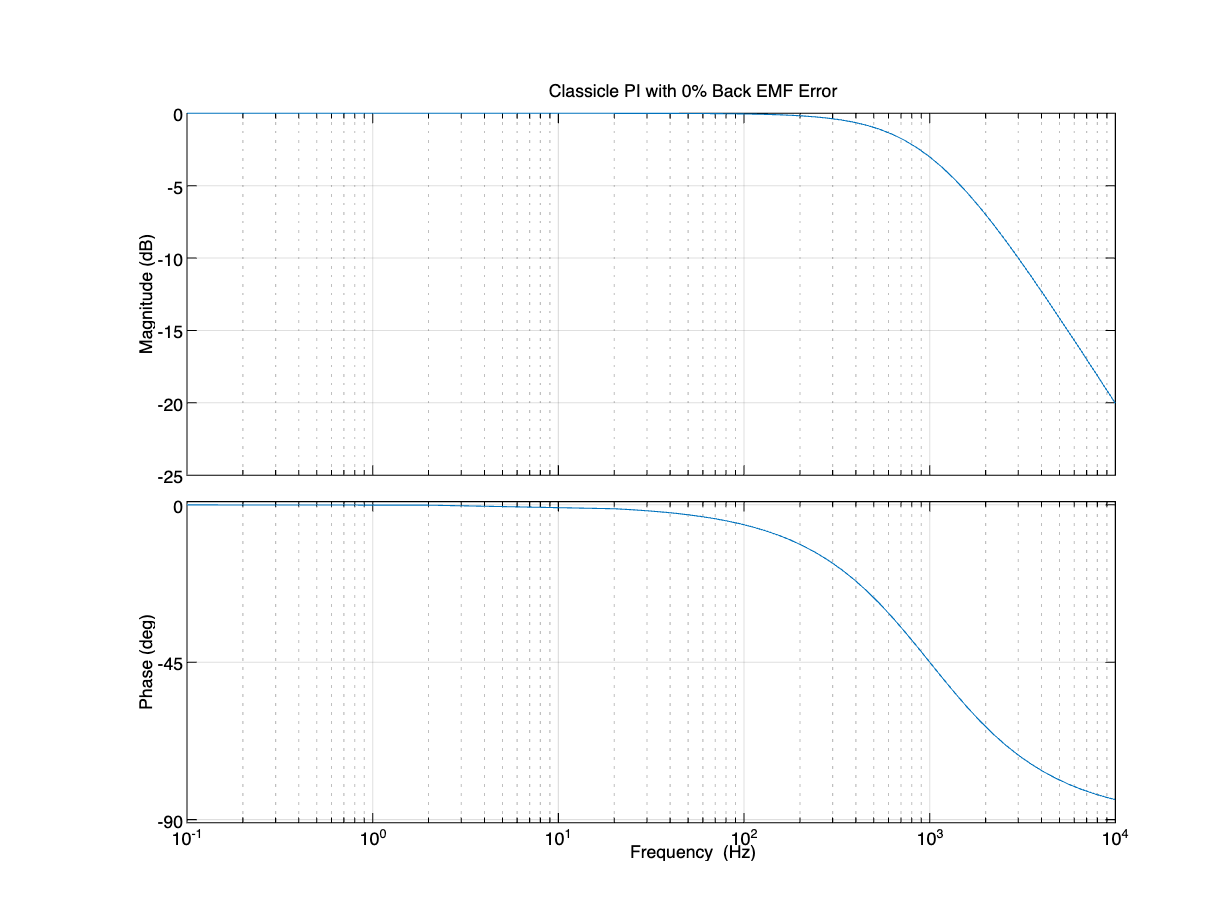

$$EQ1\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi \,s^{2}}{50000}+\frac{1001\,\pi \,s}{50000}+\frac{\pi }{50}}{\frac{401\,s}{100000}+\frac{\pi }{50}+\frac{1001\,\pi \,s}{50000}+\frac{\pi \,s^{2}}{50000}+\frac{1001\,s^{2}}{100000000}+\frac{s^{3}}{100000000}}$$

tf =
 
    6283 s^2 + 6.289e06 s + 6.283e06
  -------------------------------------
  s^3 + 7284 s^2 + 6.69e06 s + 6.283e06
 
Continuous-time transfer function.



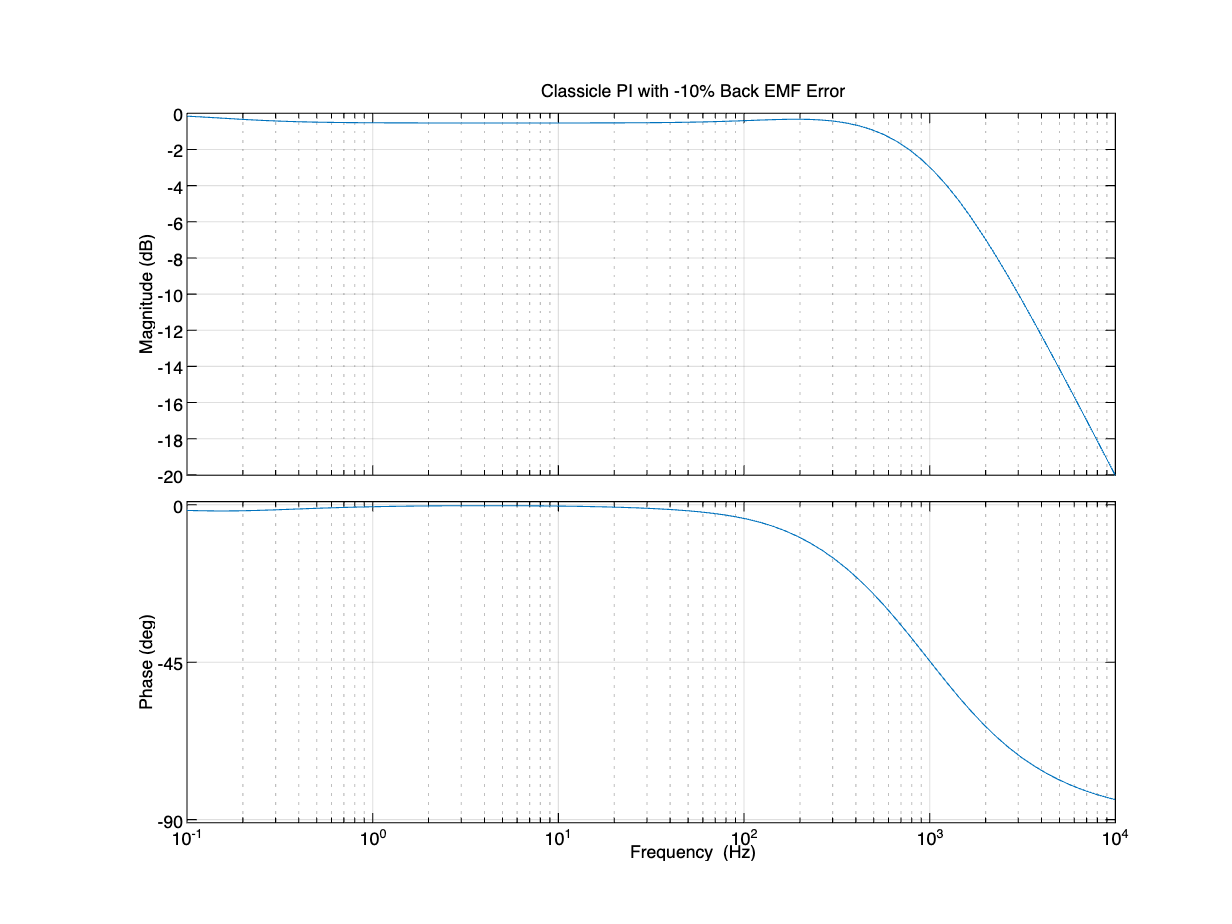

$$EQ1\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi \,s^{2}}{50000}+\frac{1001\,\pi \,s}{50000}+\frac{\pi }{50}}{\frac{\pi }{50}-\frac{399\,s}{100000}+\frac{1001\,\pi \,s}{50000}+\frac{\pi \,s^{2}}{50000}+\frac{1001\,s^{2}}{100000000}+\frac{s^{3}}{100000000}}$$

tf =
 
    6283 s^2 + 6.289e06 s + 6.283e06
  -------------------------------------
  s^3 + 7284 s^2 + 5.89e06 s + 6.283e06
 
Continuous-time transfer function.



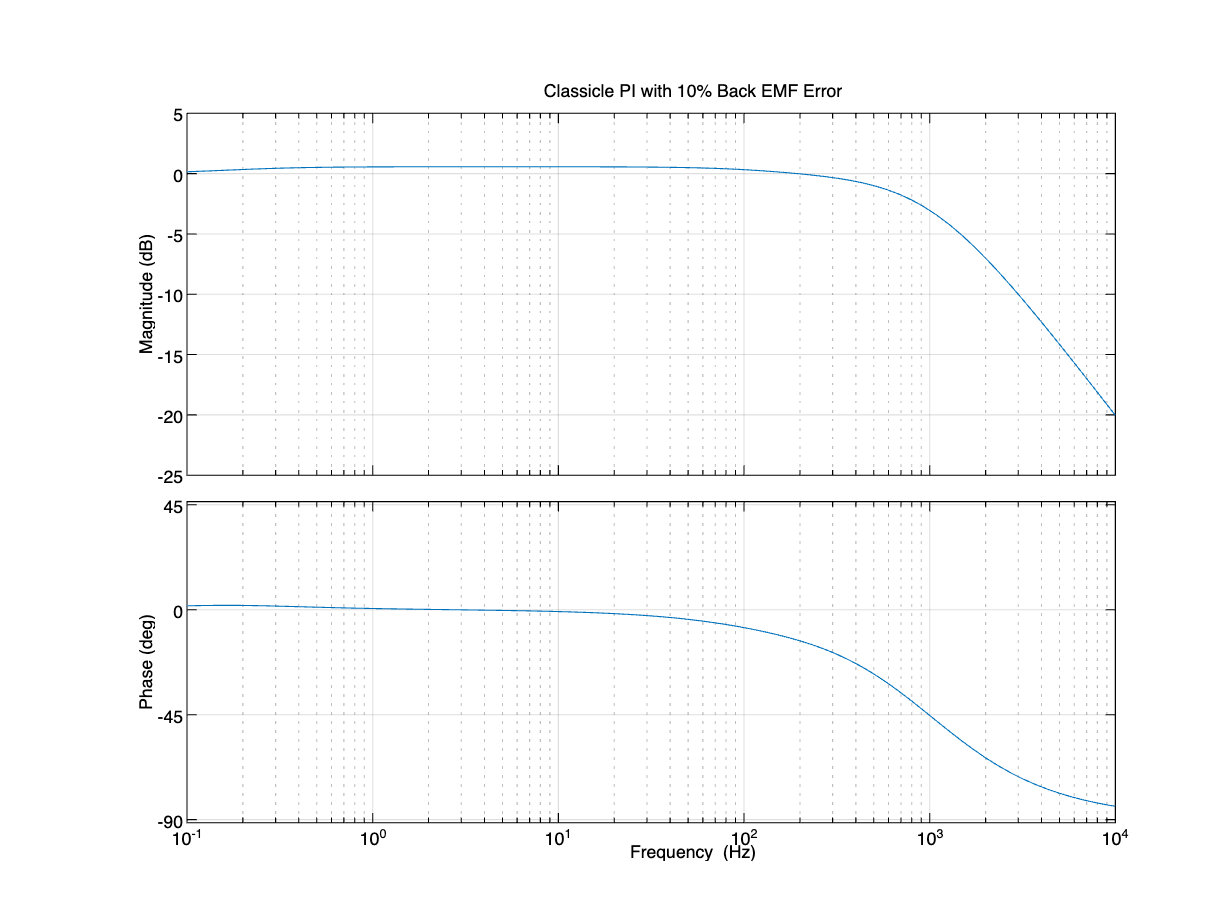

drawnow

% non-zero speed with error
K_e = 0.2;
for error = [1, 0.9, 1.1]
    K_hat_e = error*K_e;
    EQ1_tf = subs(EQ1_2)
    
    tf = syms2tf(simplify(rhs(EQ1_tf)))
    
    figure
    bodeplot(tf,opts)
    title(['Classicle PI with ', num2str((error-1)*100), '% Back EMF Error'])
    drawnow
end


% without EMF decoupling
K_e = 0.2;
K_hat_e = 0;
EQ1_tf = subs(EQ1_2)

$$EQ1\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi \,s^{2}}{50000}+\frac{1001\,\pi \,s}{50000}+\frac{\pi }{50}}{\frac{4001\,s}{100000}+\frac{\pi }{50}+\frac{1001\,\pi \,s}{50000}+\frac{\pi \,s^{2}}{50000}+\frac{1001\,s^{2}}{100000000}+\frac{s^{3}}{100000000}}$$


tf = syms2tf(simplify(rhs(EQ1_tf)))

tf =
 
     6283 s^2 + 6.289e06 s + 6.283e06
  --------------------------------------
  s^3 + 7284 s^2 + 1.029e07 s + 6.283e06
 
Continuous-time transfer function.



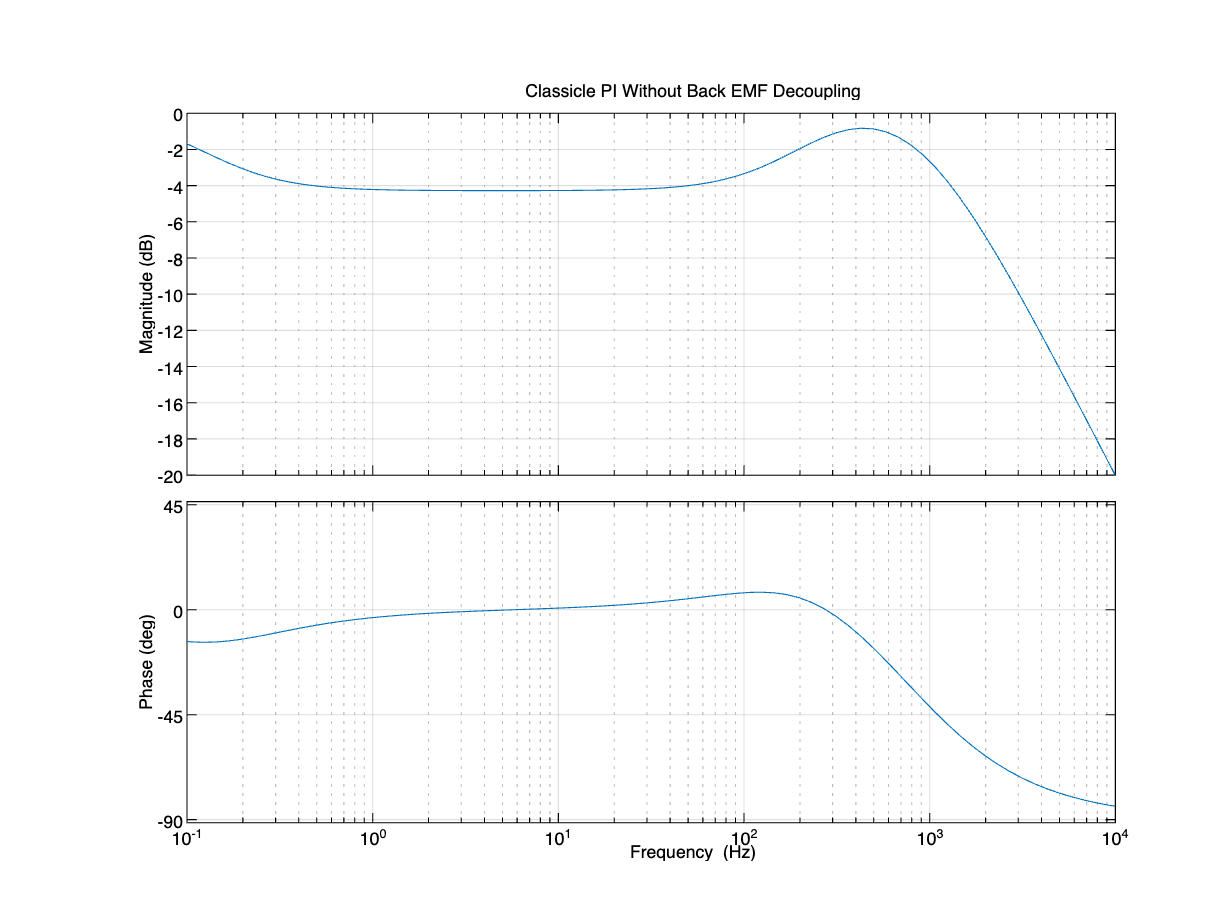


figure
bodeplot(tf,opts)
title('Classicle PI Without Back EMF Decoupling')

drawnow


## c2. Frequency Response of Current Regulator - Active Resistance

% With perfect decoupling
R_a = 2*pi*f_desired*L_p

R_a = 6.2832

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}}$$

tf =
 
    6283
  --------
  s + 6283
 
Continuous-time transfer function.



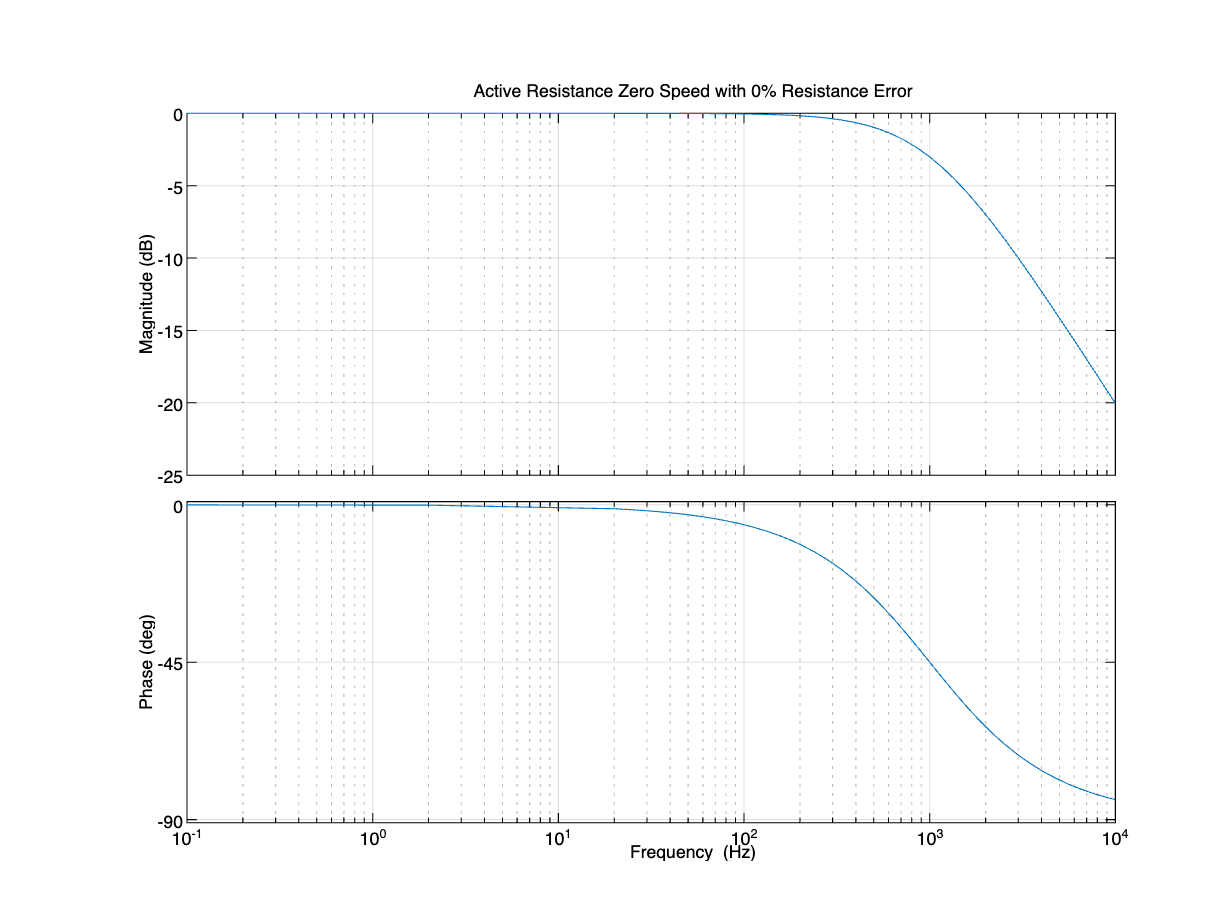

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{201\,s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}+\frac{1}{500000}}$$

tf =
 
    6283
  --------
  s + 6483
 
Continuous-time transfer function.



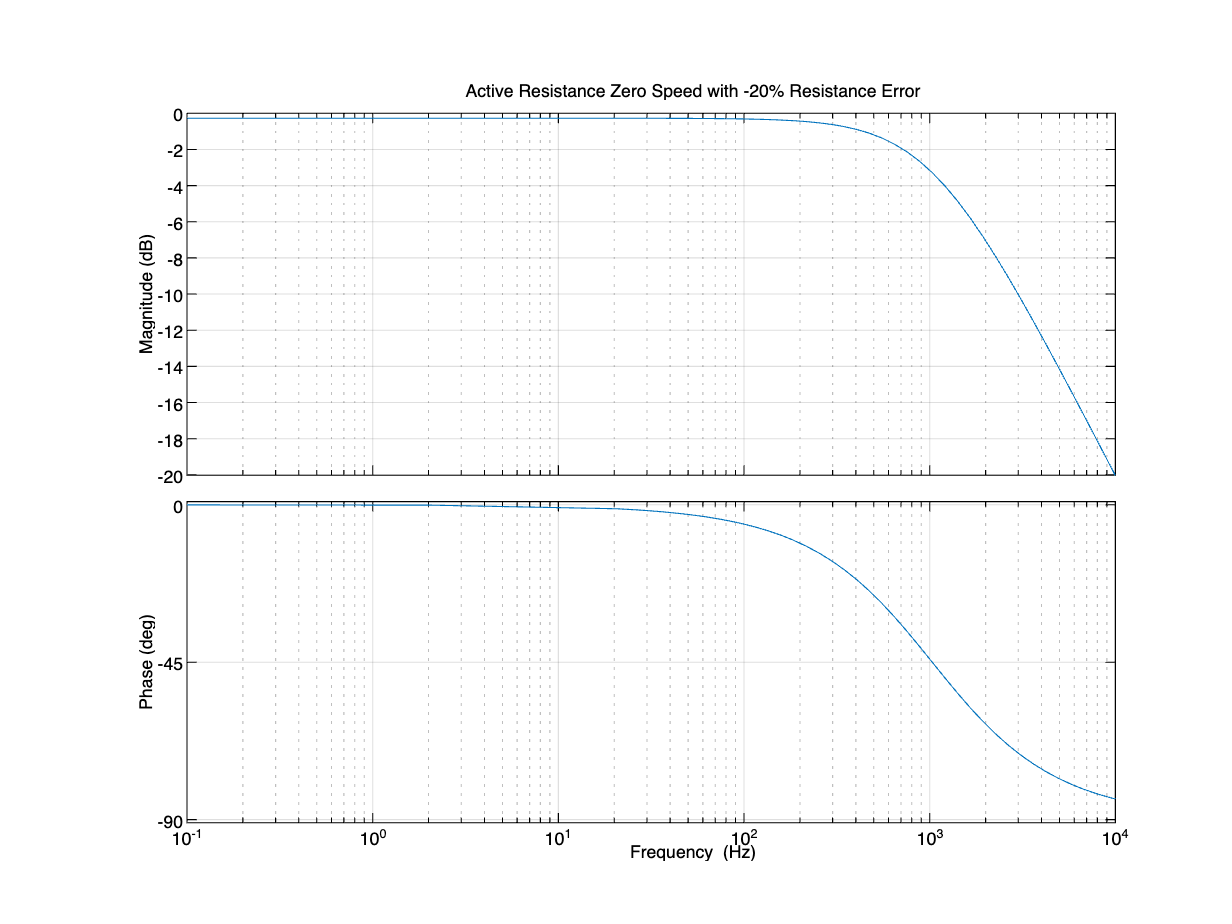

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{\pi }{50000}-\frac{199\,s}{100000000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}-\frac{1}{500000}}$$

tf =
 
    6283
  --------
  s + 6083
 
Continuous-time transfer function.



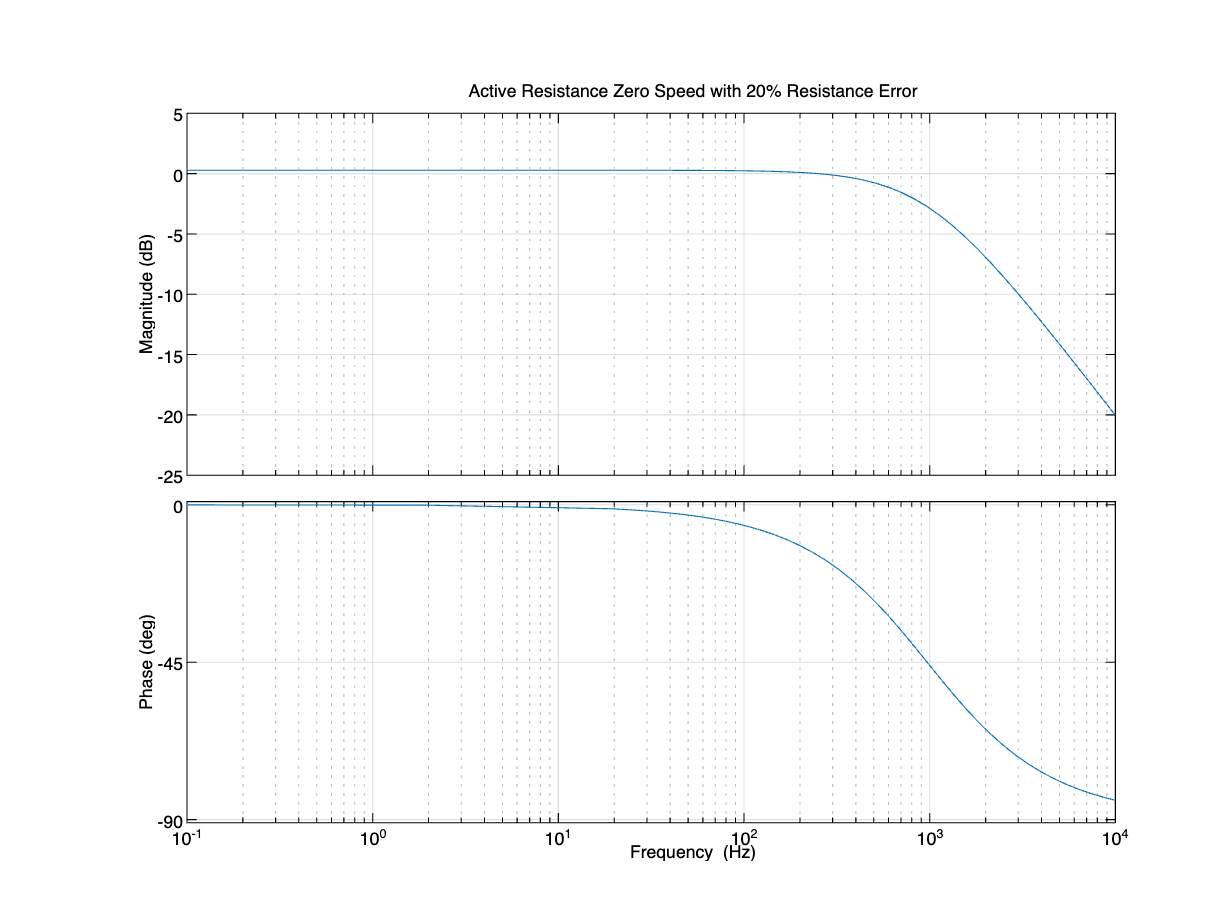



% zero speed with different R_p error
K_e = 0;
K_hat_e = 0;

for Rerror = [1, 0.8, 1.2]
    R_hat_p = Rerror*R_p;

    EQ2_tf = subs(EQ2_2)
    tf = syms2tf(simplify(rhs(EQ2_tf)))

    figure
    bodeplot(tf,opts)
    title(['Active Resistance Zero Speed with ', num2str((Rerror-1)*100), '% Resistance Error'])
    drawnow
end

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}}$$

tf =
 
    6283
  --------
  s + 6283
 
Continuous-time transfer function.



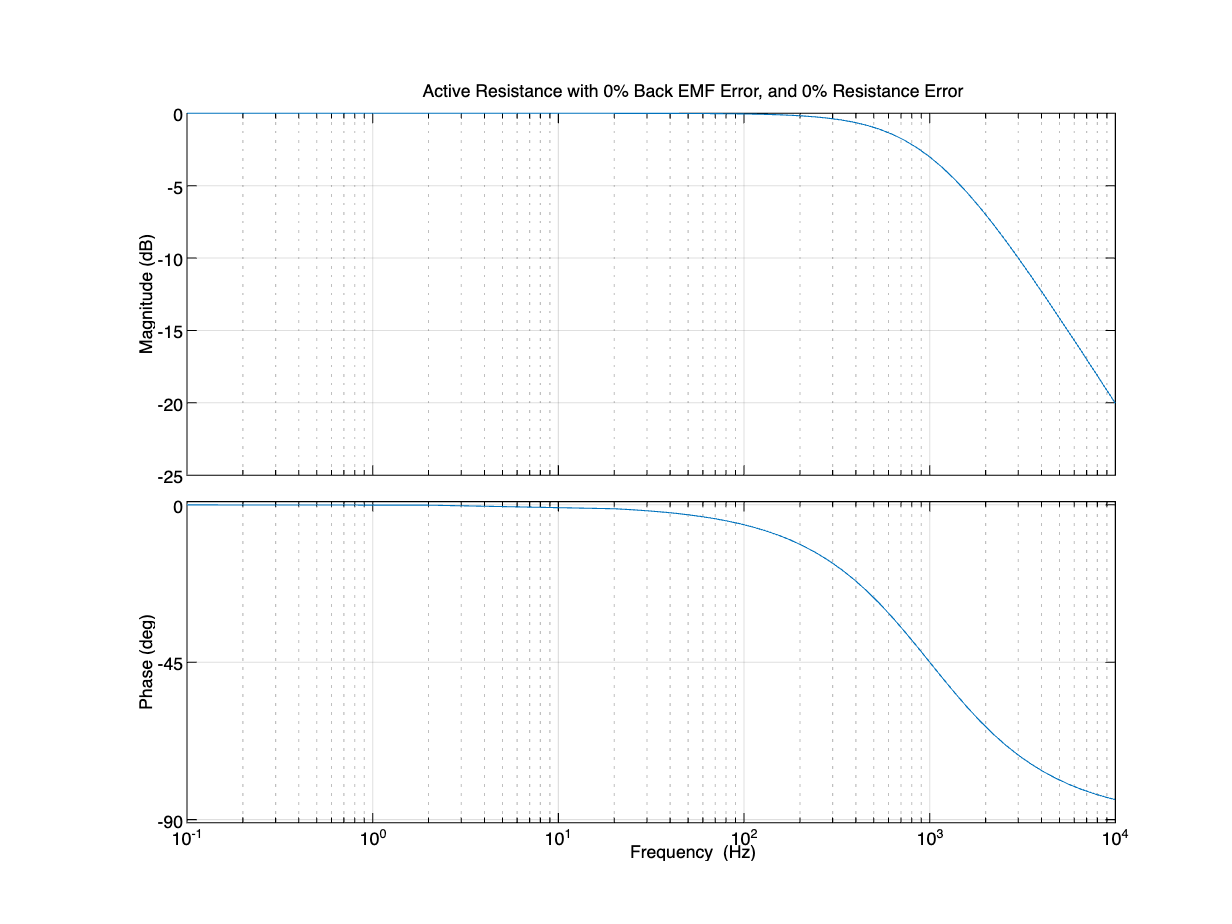

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}+\frac{1}{250}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6284 s + 4.063e05
 
Continuous-time transfer function.



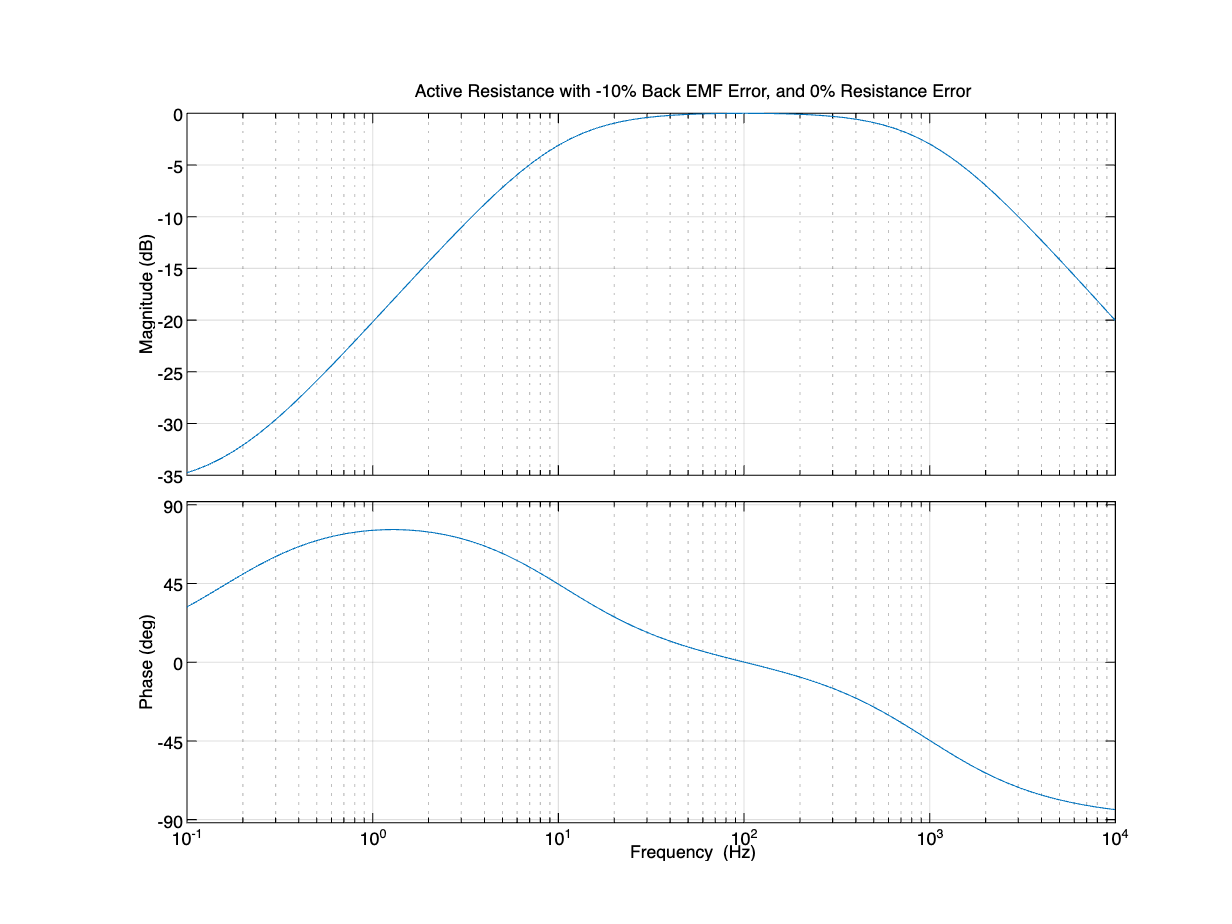

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}-\frac{1}{250}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6284 s - 3.937e05
 
Continuous-time transfer function.



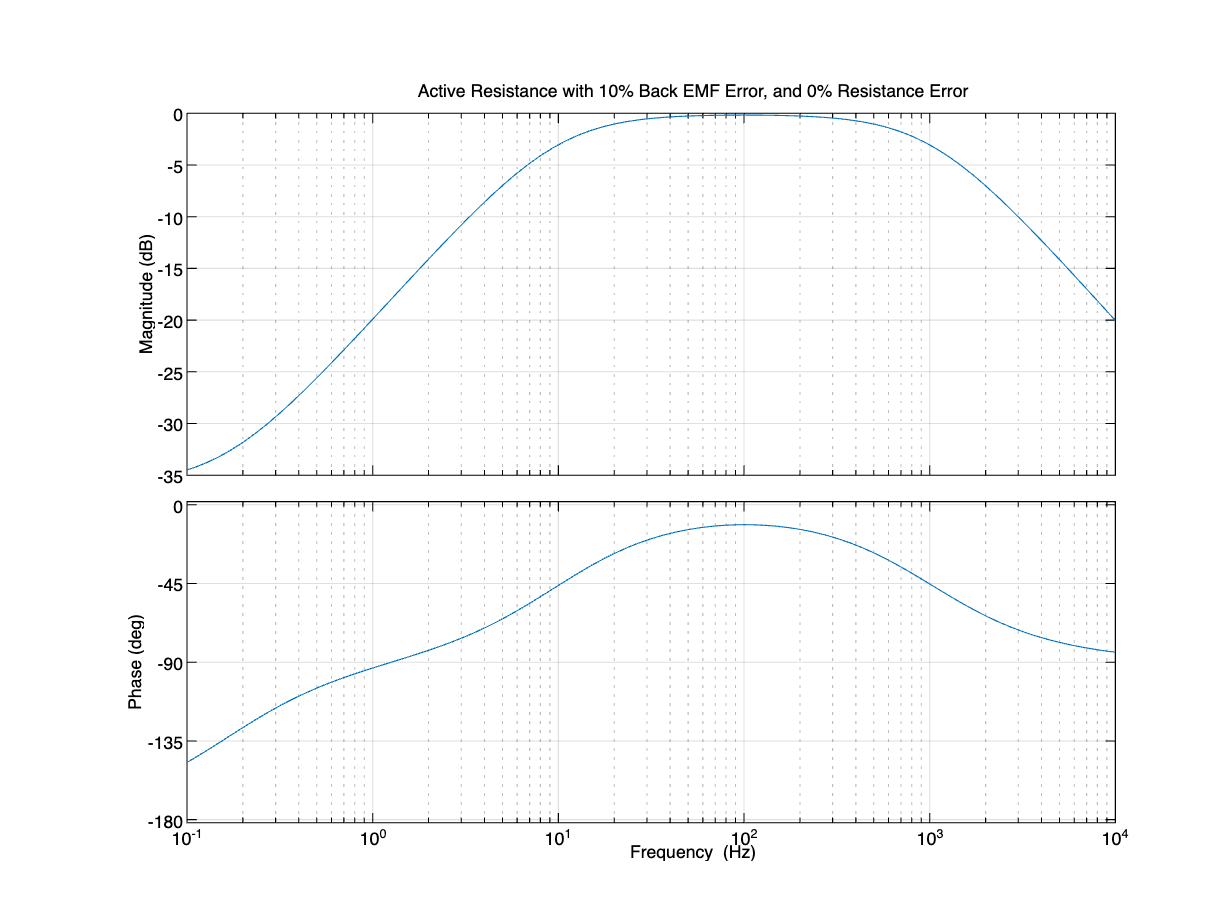

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{201\,s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}+\frac{1}{500000}}$$

tf =
 
    6283
  --------
  s + 6483
 
Continuous-time transfer function.



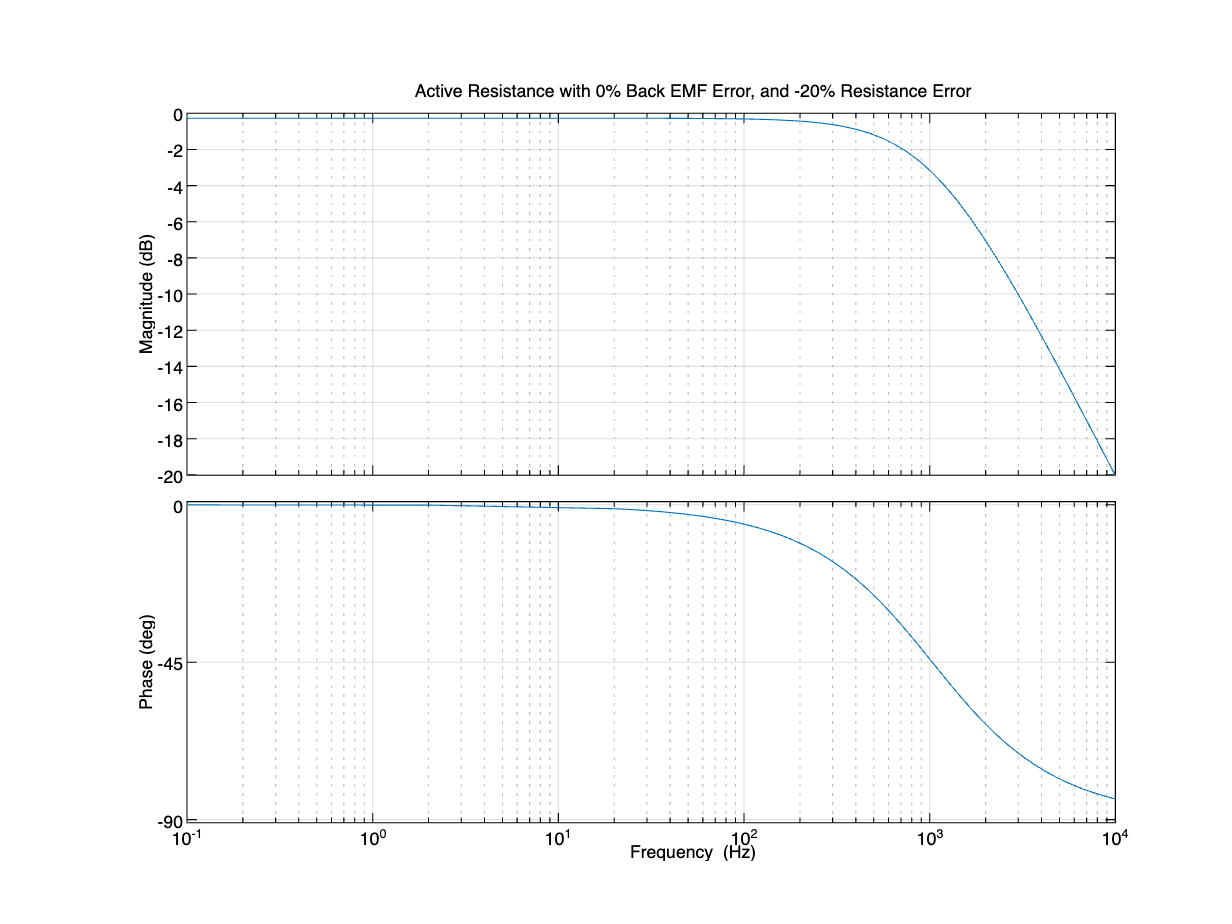

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{201\,s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}+\frac{2001}{500000}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6484 s + 4.065e05
 
Continuous-time transfer function.



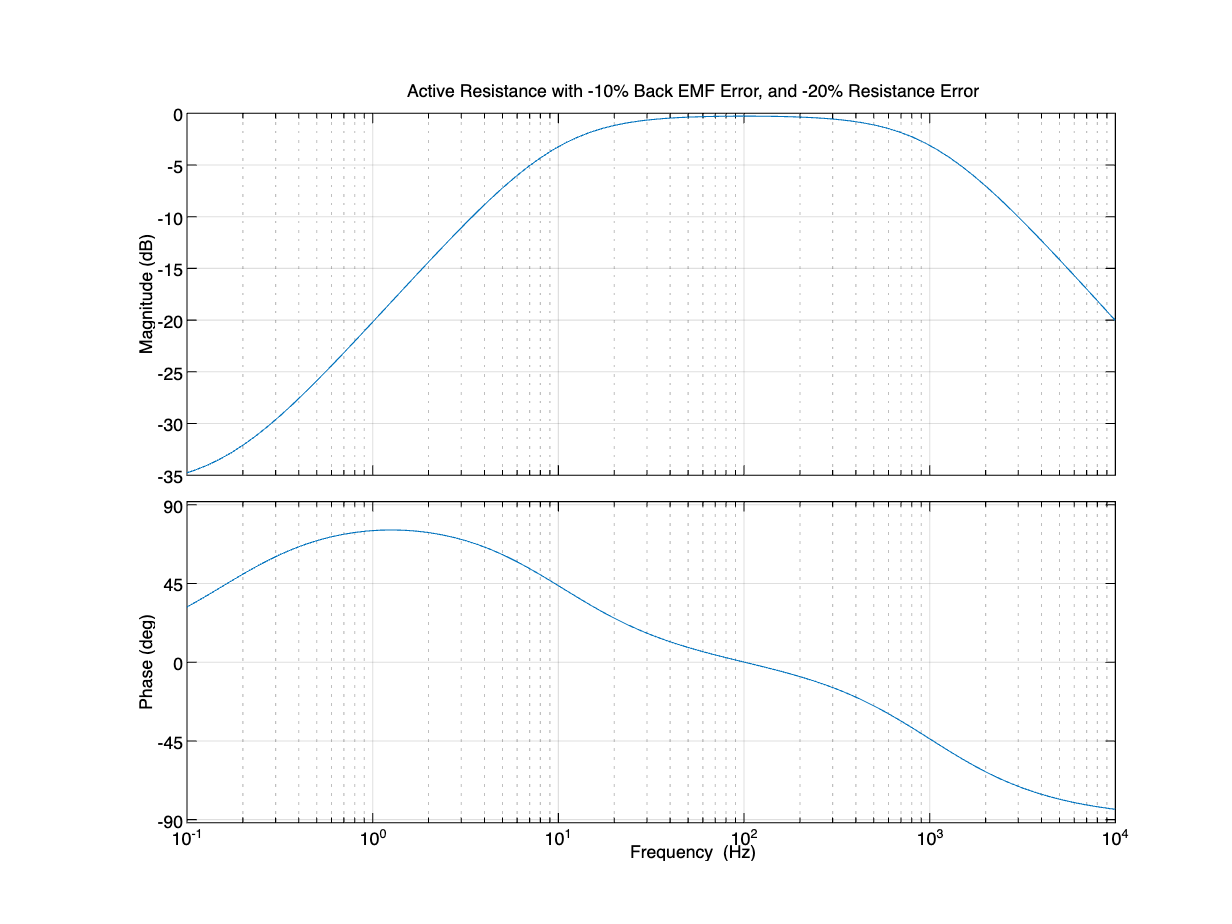

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{201\,s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}-\frac{1999}{500000}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6484 s - 3.935e05
 
Continuous-time transfer function.



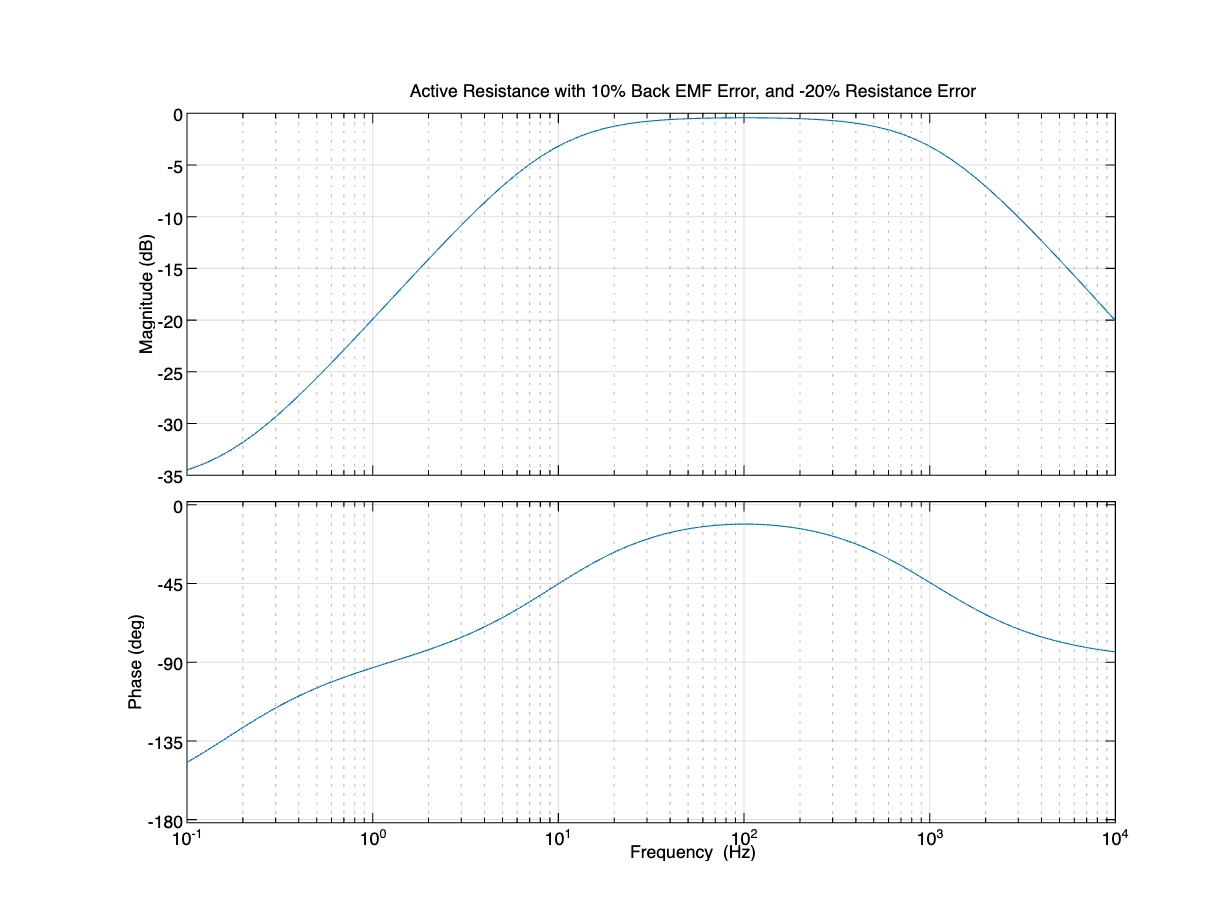

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{\pi }{50000}-\frac{199\,s}{100000000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}-\frac{1}{500000}}$$

tf =
 
    6283
  --------
  s + 6083
 
Continuous-time transfer function.



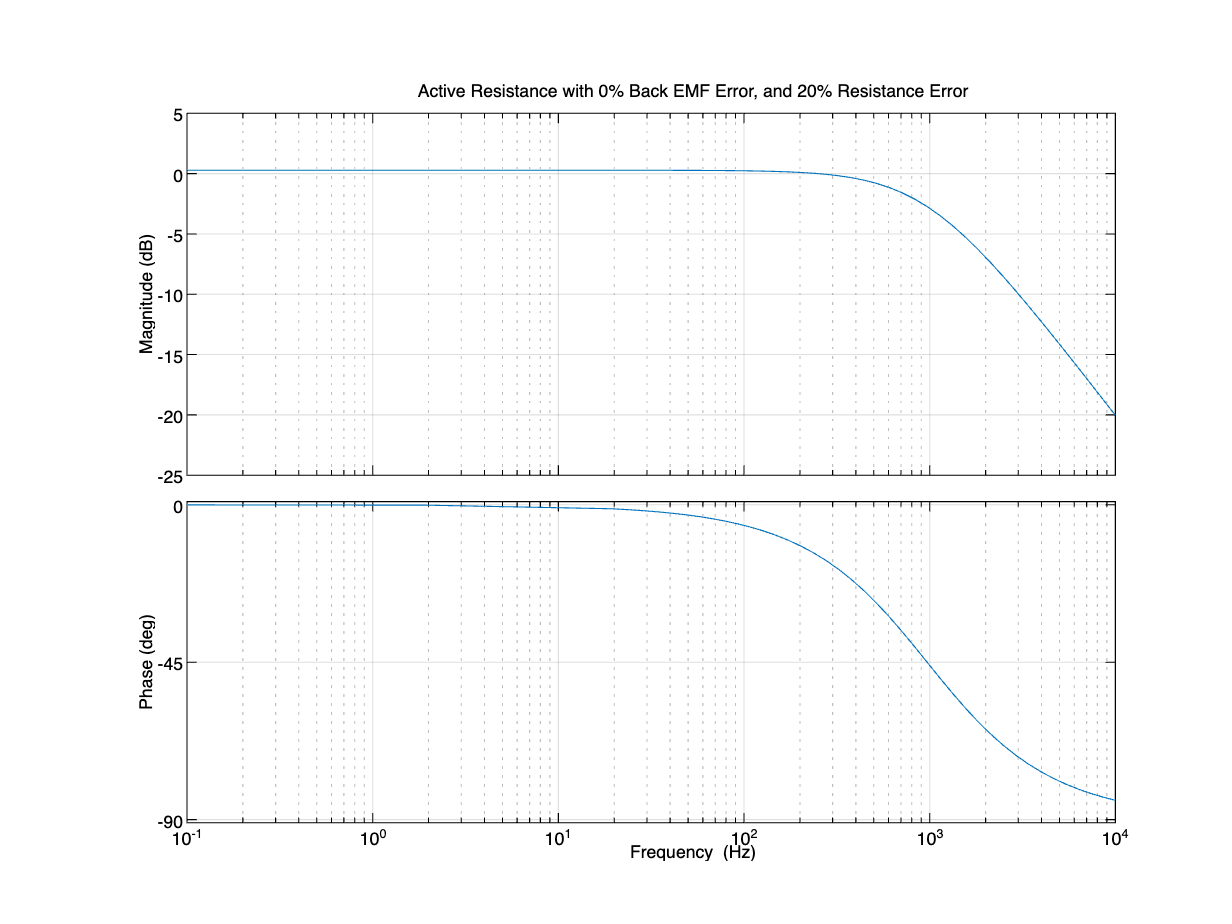

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{\pi }{50000}-\frac{199\,s}{100000000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}+\frac{1999}{500000}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6084 s + 4.061e05
 
Continuous-time transfer function.



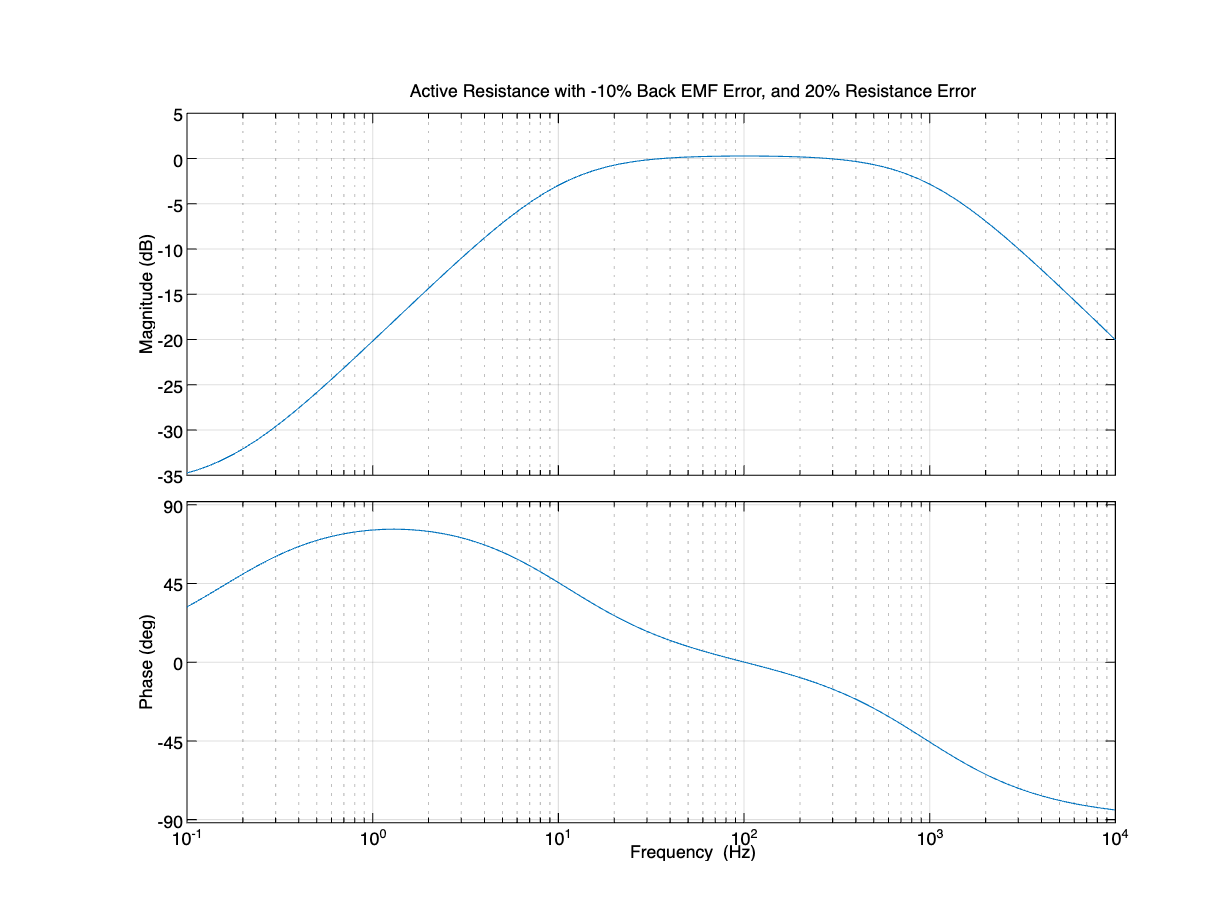

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{\pi }{50000}-\frac{199\,s}{100000000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}-\frac{2001}{500000}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6084 s - 3.939e05
 
Continuous-time transfer function.



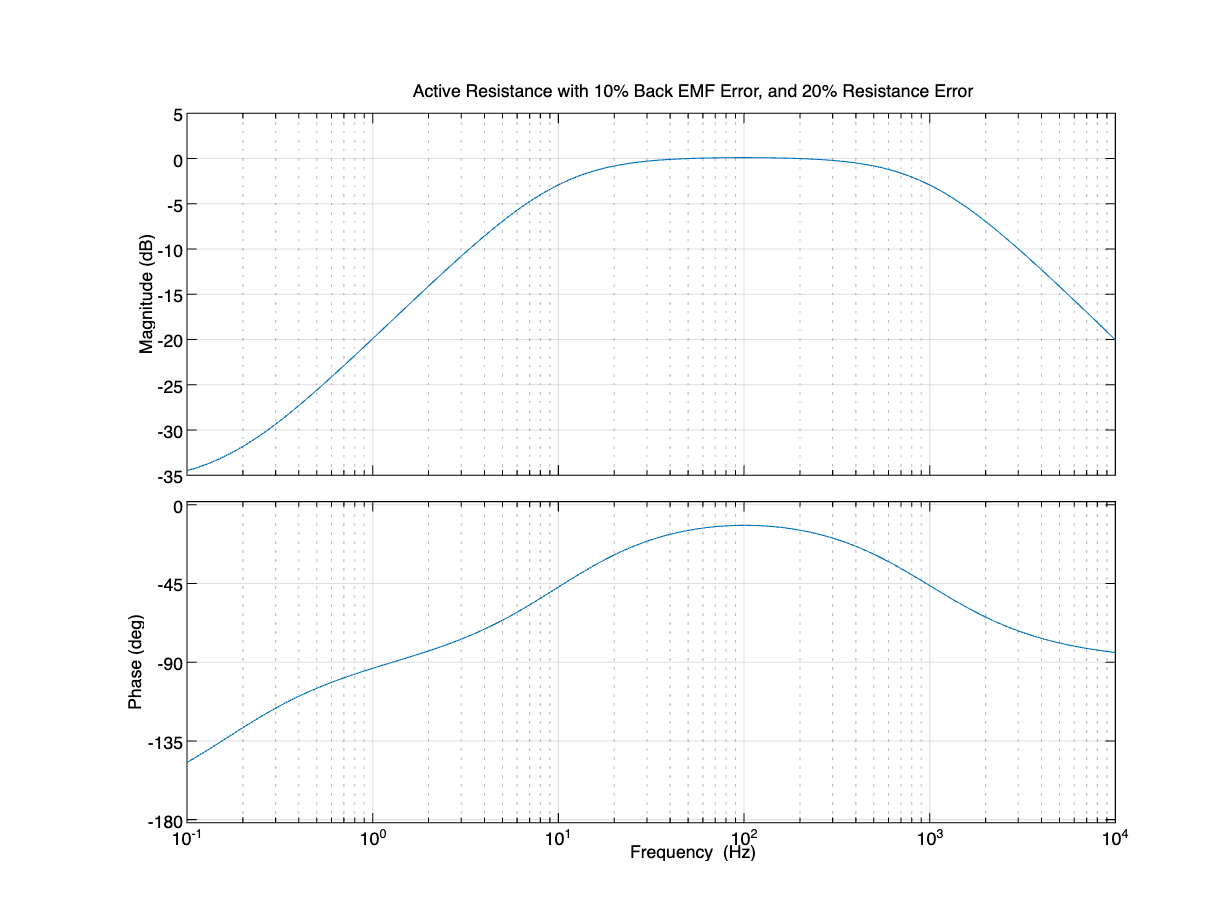



% non-zero speed with EMF and resistance error
K_e = 0.2;
for Rerror = [1, 0.8, 1.2]          % Resistance error
    for Kerror = [1, 0.9, 1.1]      % EMF error
        R_hat_p = Rerror*R_p;
        K_hat_e = Kerror*K_e;

        EQ2_tf = subs(EQ2_2)
        tf = syms2tf(simplify(rhs(EQ2_tf)))
    
        figure
        bodeplot(tf,opts)
        title(['Active Resistance with ', num2str((Kerror-1)*100), '% Back EMF Error, and ', num2str((Rerror-1)*100), '% Resistance Error'])
        drawnow
    end
end

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}+\frac{1}{25}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6284 s + 4.006e06
 
Continuous-time transfer function.



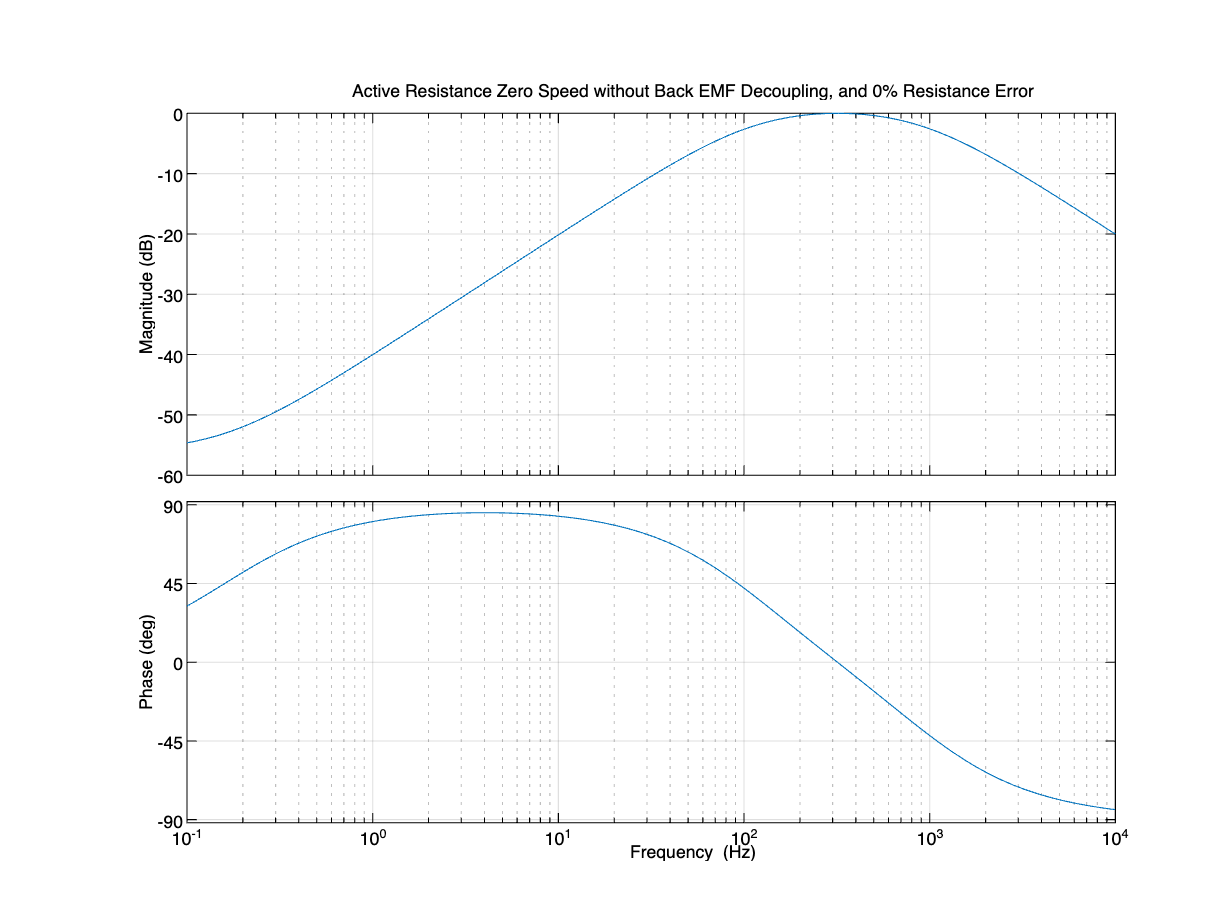

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{201\,s}{100000000}+\frac{\pi }{50000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}+\frac{20001}{500000}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6484 s + 4.006e06
 
Continuous-time transfer function.



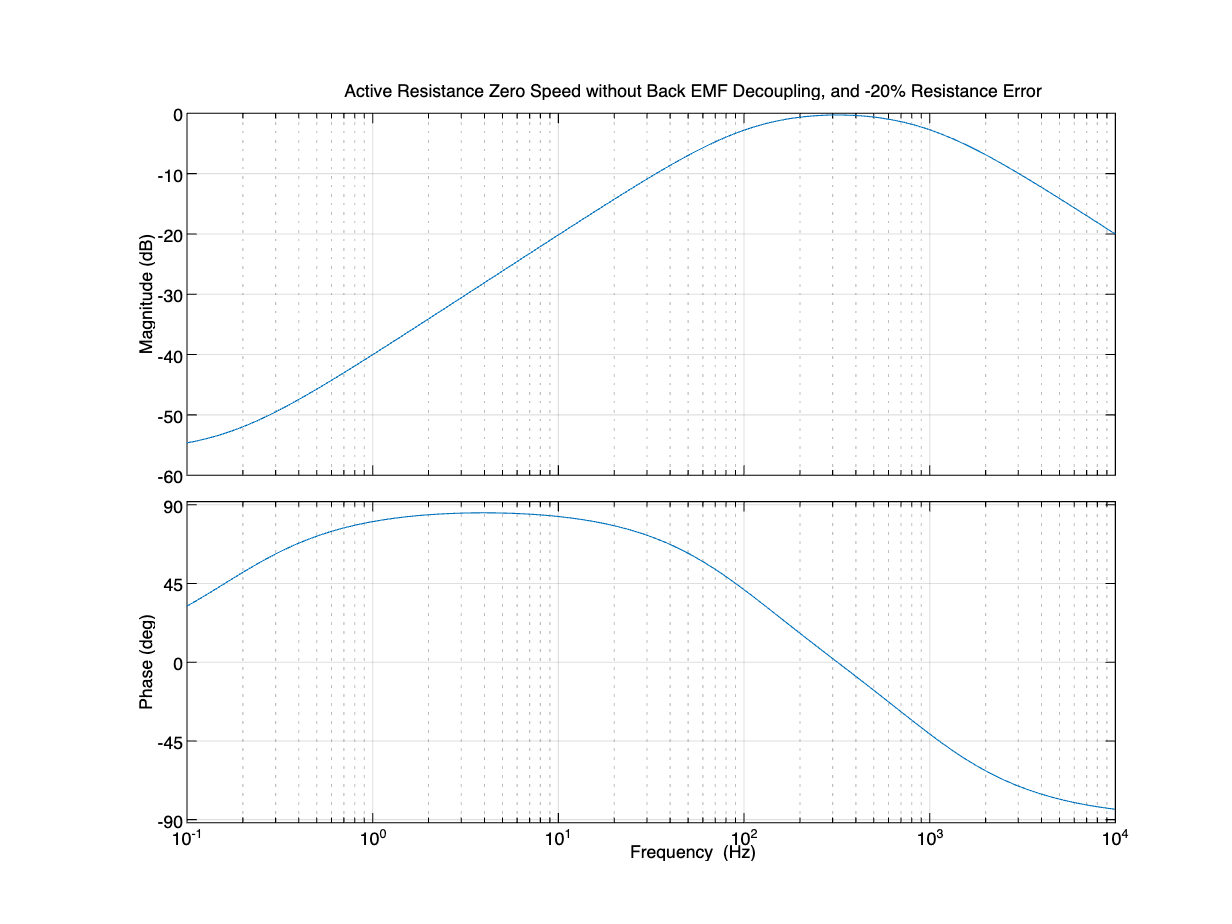

$$EQ2\_tf = \frac{i}{i^{*}}=\frac{\frac{\pi }{50000}+\frac{\pi \,s}{50000}}{\frac{\pi }{50000}-\frac{199\,s}{100000000}+\frac{\pi \,s}{50000}+\frac{s^{2}}{100000000}+\frac{19999}{500000}}$$

tf =
 
       6283 s + 6283
  -----------------------
  s^2 + 6084 s + 4.006e06
 
Continuous-time transfer function.



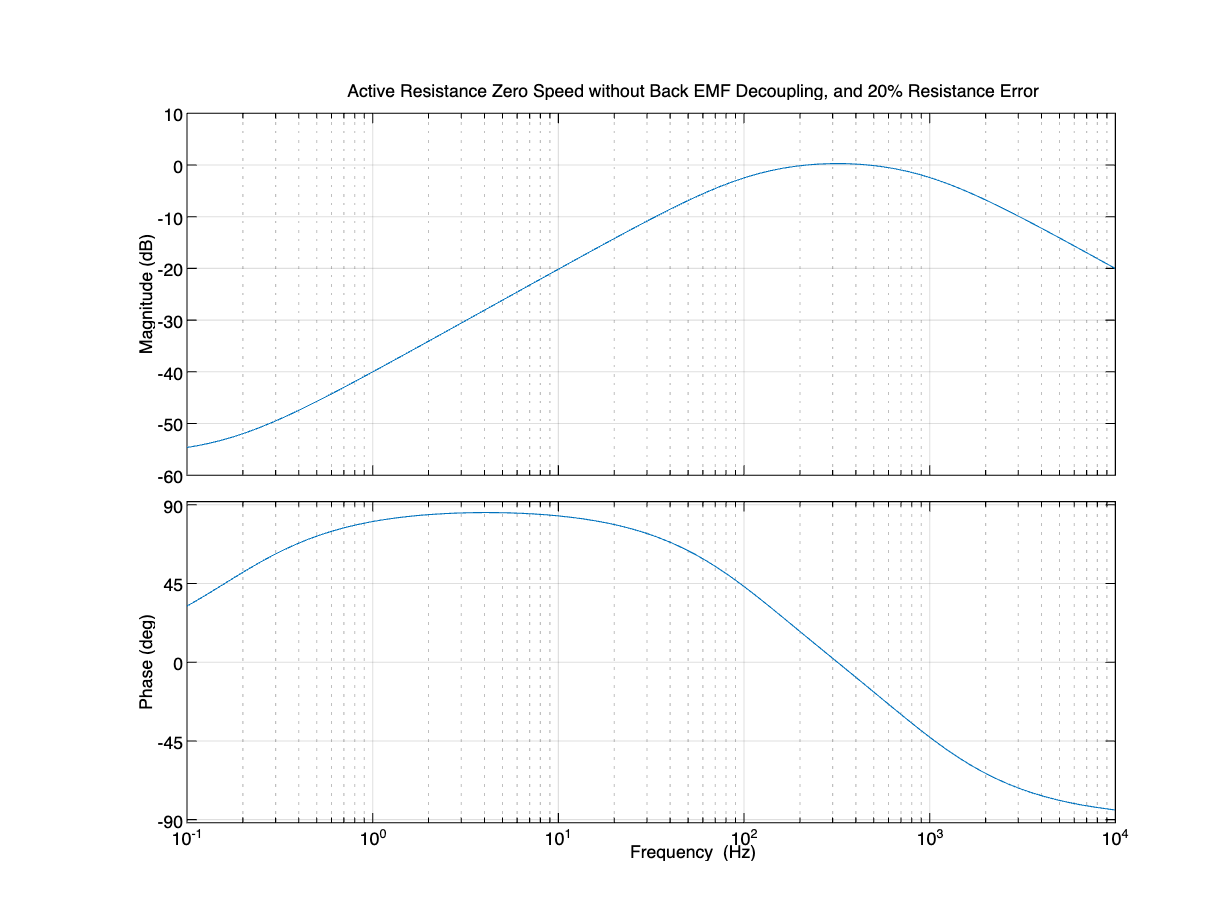



% without EMF decoupling
K_e = 0.2;
K_hat_e = 0;
for Rerror = [1, 0.8, 1.2]
    R_hat_p = Rerror*R_p;

    EQ2_tf = subs(EQ2_2)
    tf = syms2tf(simplify(rhs(EQ2_tf)))

    figure
    bodeplot(tf,opts)
    title(['Active Resistance Zero Speed without Back EMF Decoupling, and ', num2str((Rerror-1)*100), '% Resistance Error'])
    drawnow
end

## d1. Current Response - Classical PI

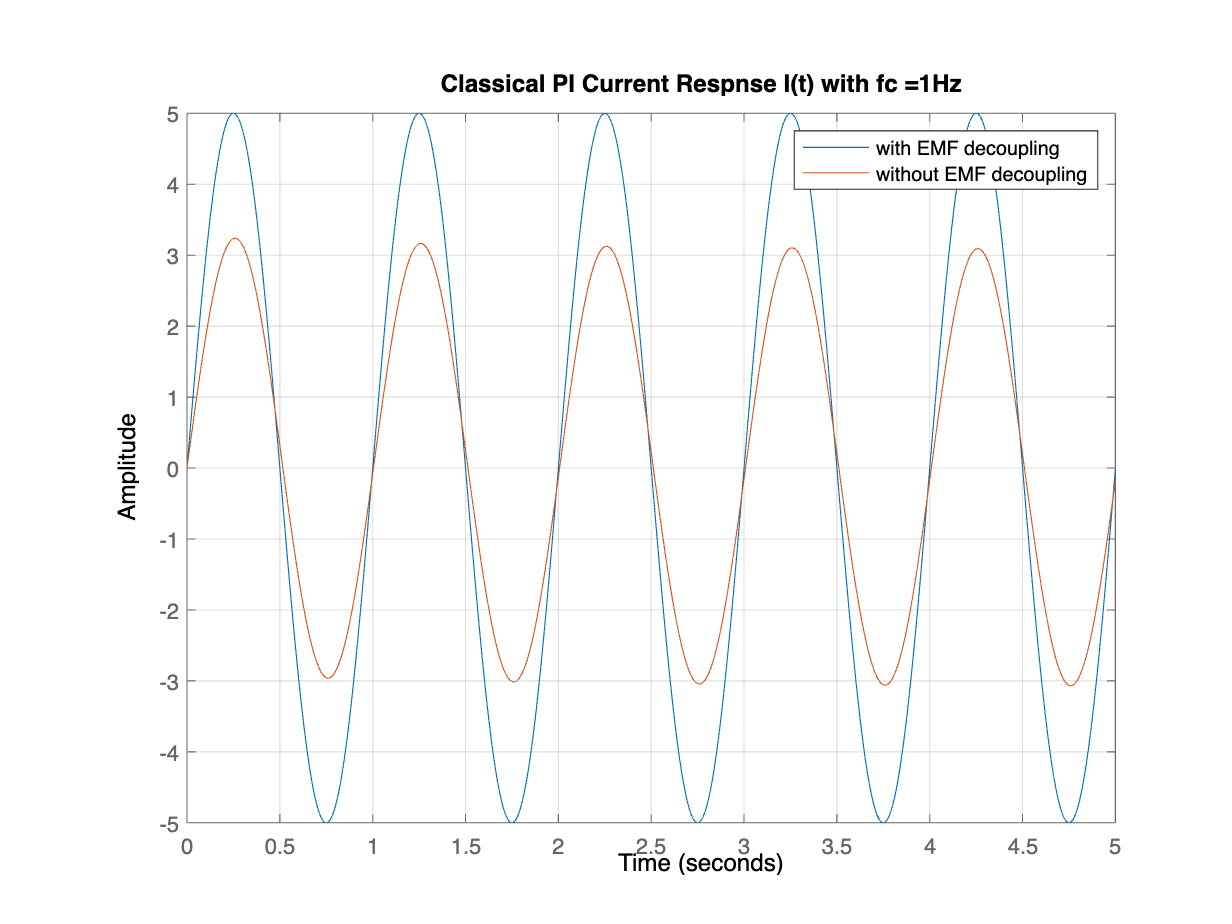

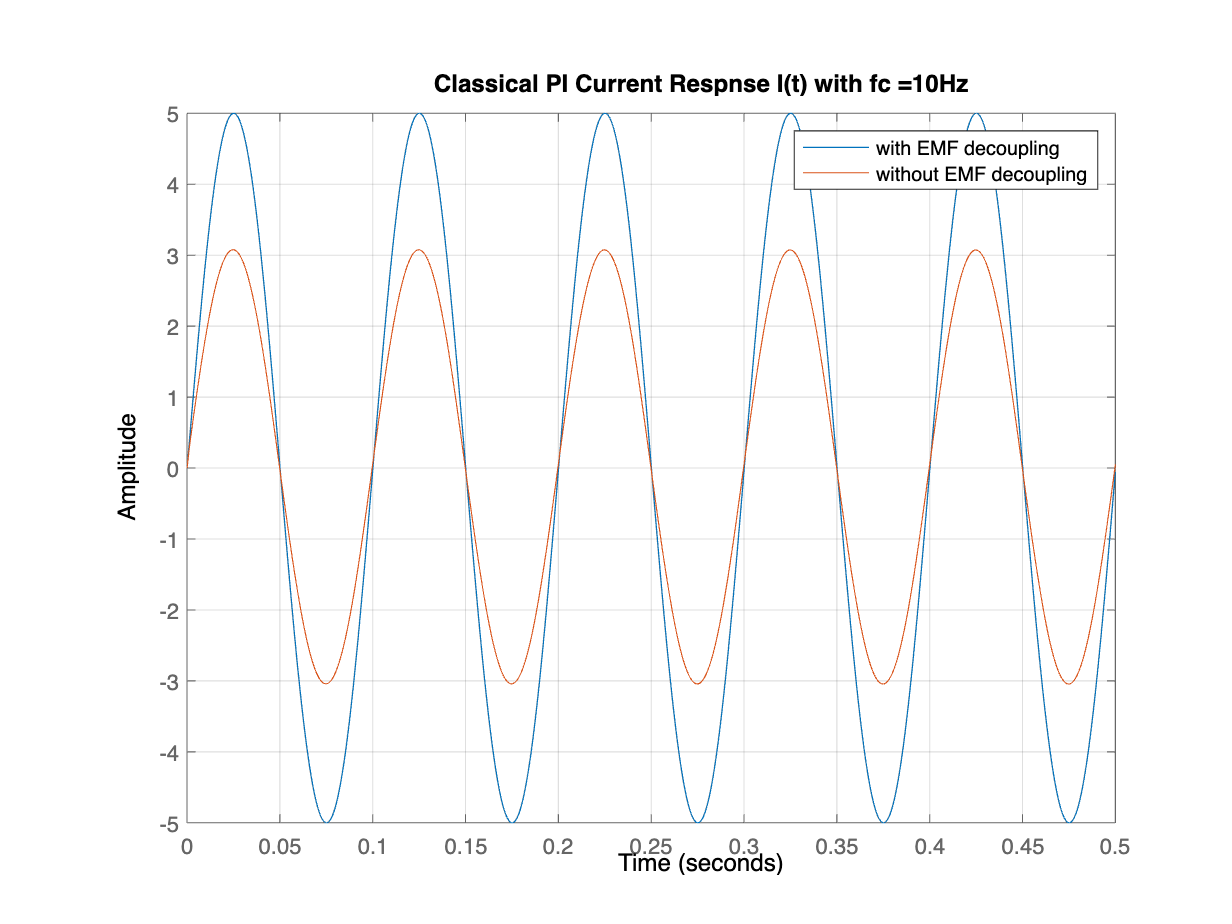

syms f_c t

K_e = 0.2;
I_0 = 5;

n = 1;

for f_c = [1, 10]
    % with EMF decoupling
    K_hat_e = K_e;
    EQ1_tf1 = subs(EQ1_2);
    tf1 = syms2tf(simplify(rhs(EQ1_tf1)));
    
    % without EMF decoupling
    K_hat_e = 0;
    EQ1_tf2 = subs(EQ1_2);
    tf2 = syms2tf(simplify(rhs(EQ1_tf2)));

    t = 0:(0.001/f_c):(5/f_c);
    i_ast_t = I_0 * sin(2*pi*f_c*t);
    
    figure
    lsim(tf1, tf2, i_ast_t,t)
    legend('with EMF decoupling', 'without EMF decoupling')
    grid on
    title(['Classical PI Current Respnse I(t) with fc =',num2str(f_c),'Hz'])
    drawnow
end

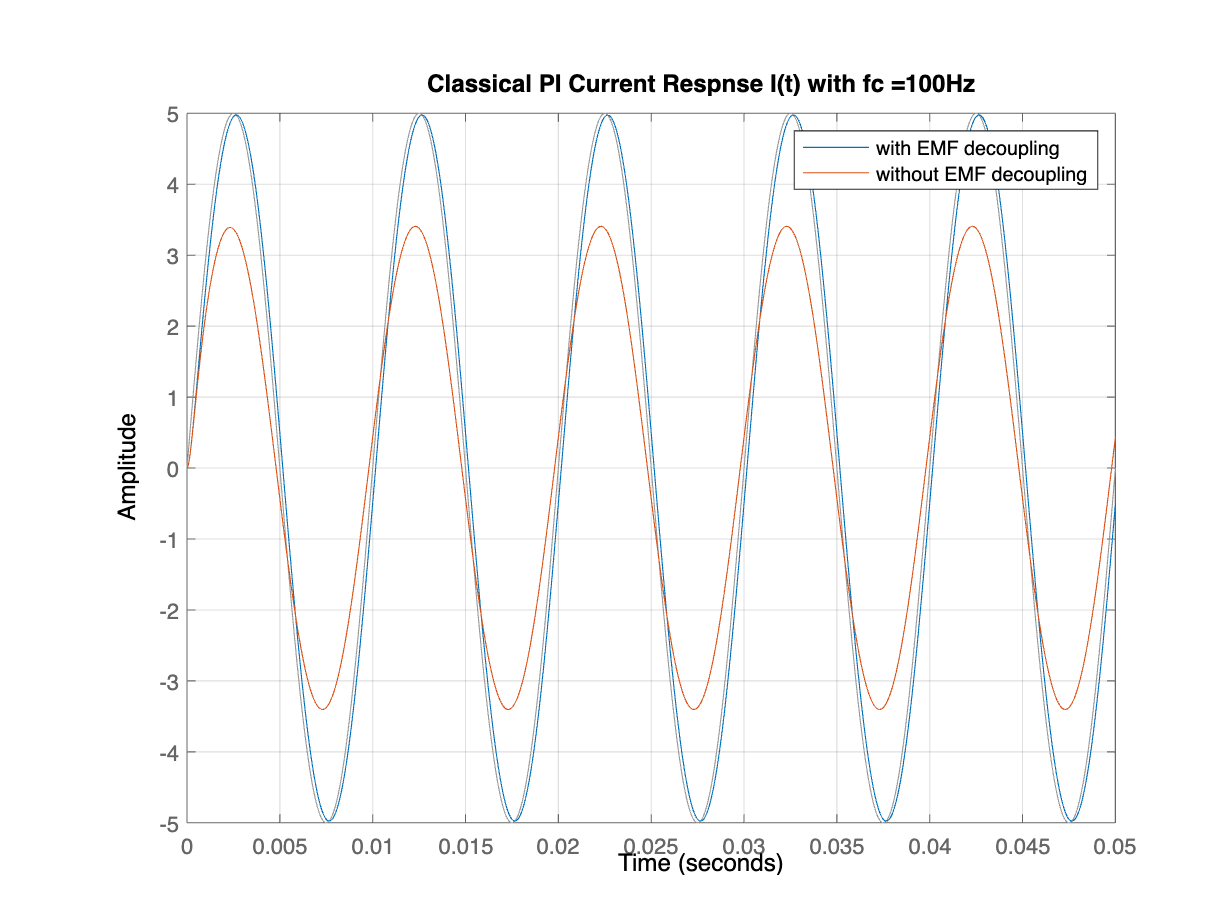

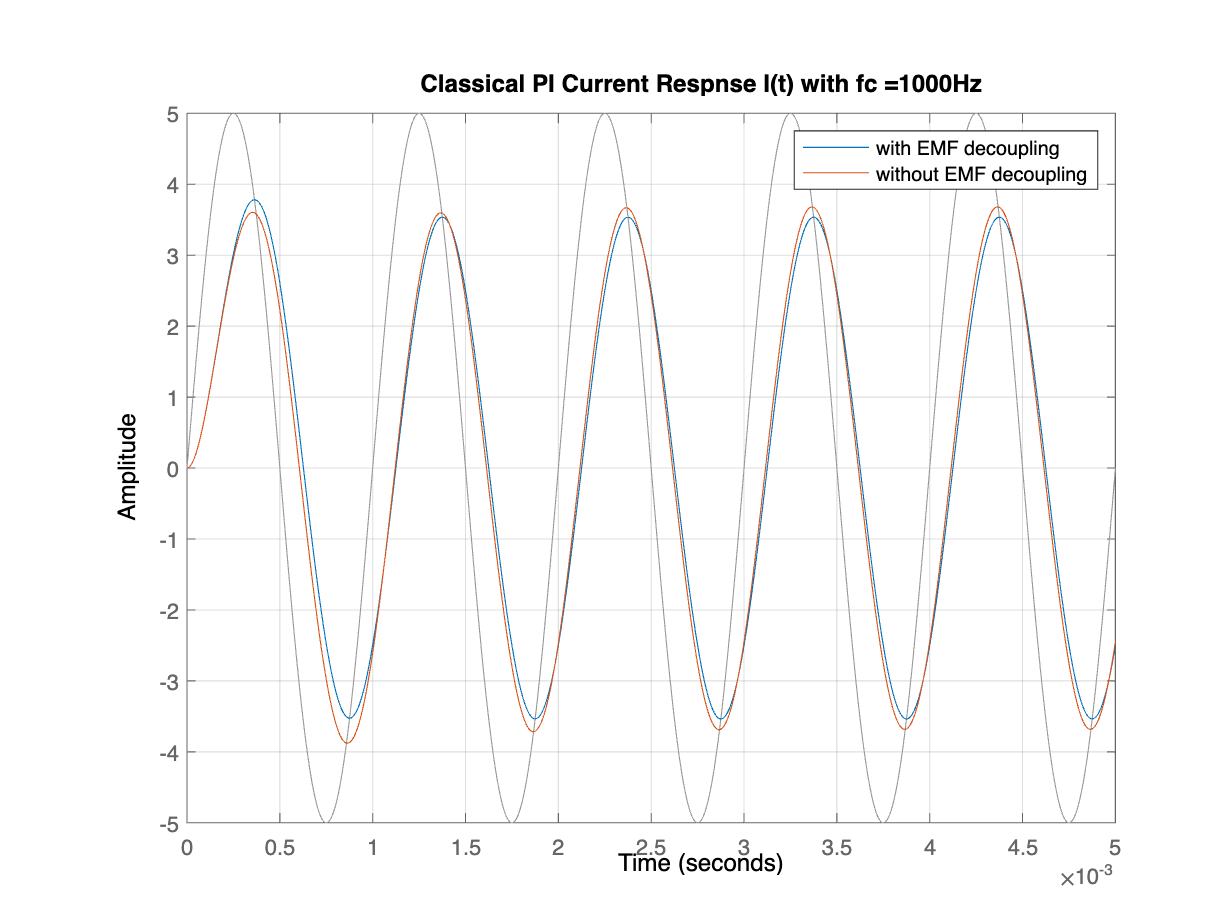

for f_c = [100, 1000]
    % with EMF decoupling
    K_hat_e = K_e;
    EQ1_tf1 = subs(EQ1_2);
    tf1 = syms2tf(simplify(rhs(EQ1_tf1)));
    
    % without EMF decoupling
    K_hat_e = 0;
    EQ1_tf2 = subs(EQ1_2);
    tf2 = syms2tf(simplify(rhs(EQ1_tf2)));

    t = 0:(0.001/f_c):(5/f_c);
    i_ast_t = I_0 * sin(2*pi*f_c*t);
    
    figure
    lsim(tf1, tf2, i_ast_t,t)
    legend('with EMF decoupling', 'without EMF decoupling')
    grid on
    title(['Classical PI Current Respnse I(t) with fc =',num2str(f_c),'Hz'])
    drawnow
end

## d2. Current Response - Active Resistance

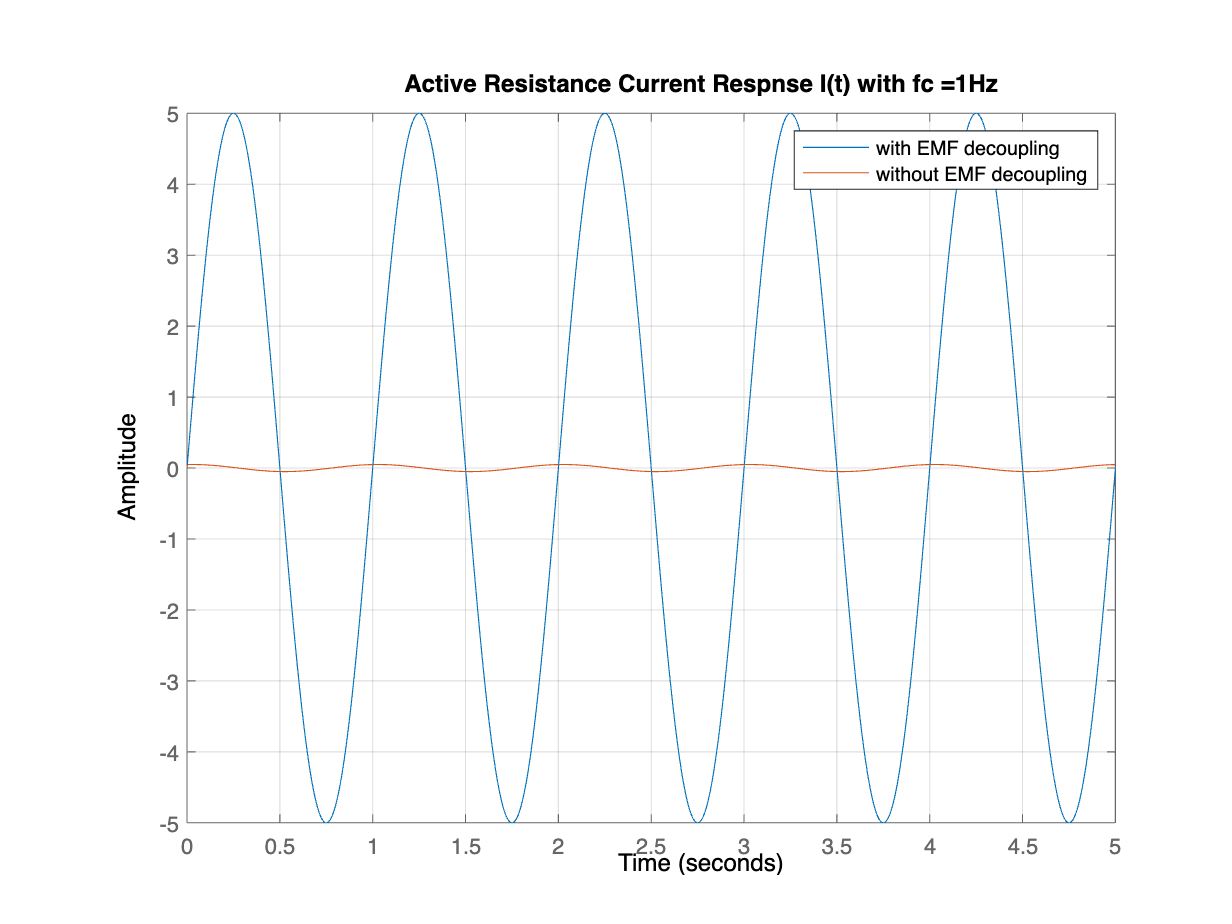

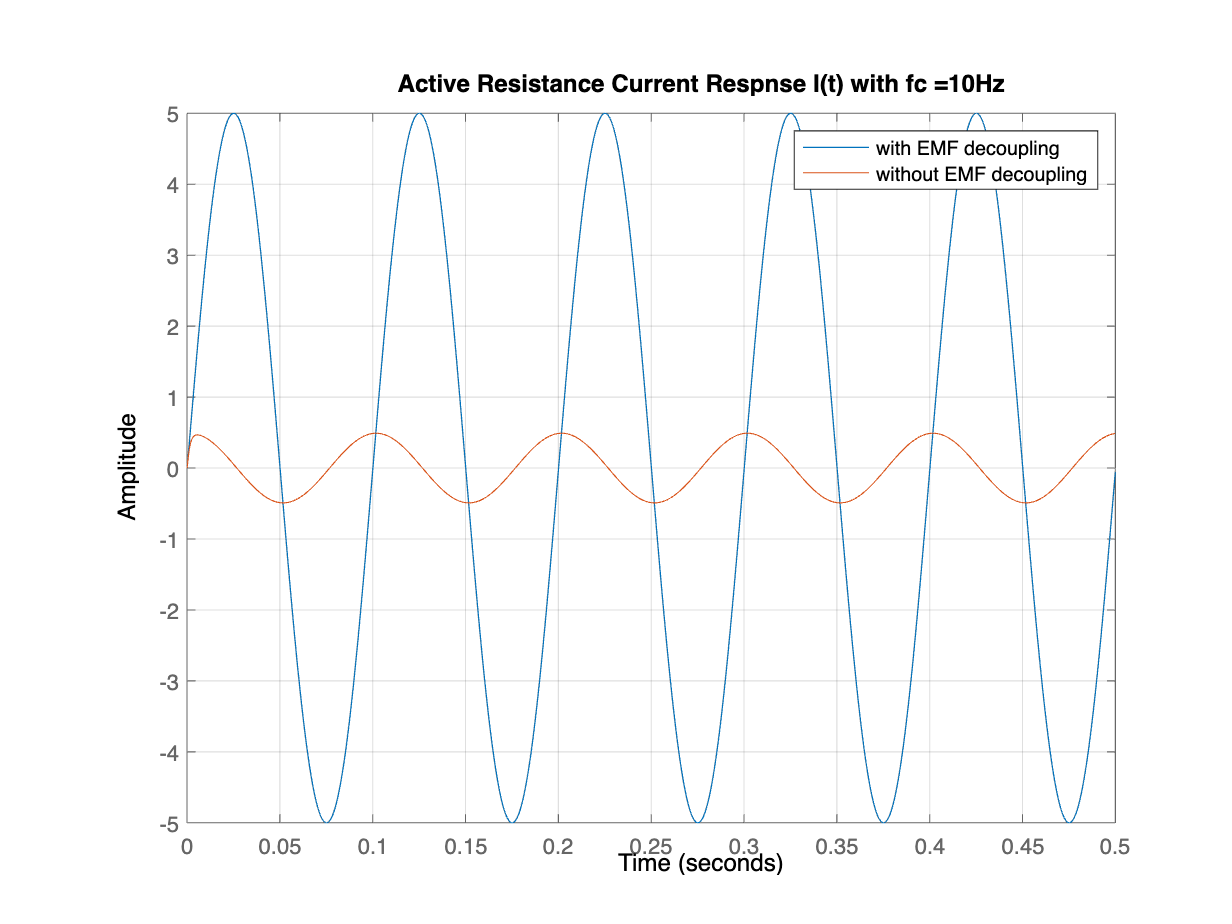

K_e = 0.2;
R_hat_p = R_p;
I_0 = 5;

for f_c = [1, 10]
    % with EMF decoupling
    K_hat_e = 0.2;
    EQ2_tf1 = subs(EQ2_2);
    tf1 = syms2tf(simplify(rhs(EQ2_tf1)));
    
    % without EMF decoupling
    K_hat_e = 0;
    EQ2_tf2 = subs(EQ2_2);
    tf2 = syms2tf(simplify(rhs(EQ2_tf2)));

    t = 0:(0.001/f_c):(5/f_c);
    i_ast_t = I_0 * sin(2*pi*f_c*t);
    
    figure
    lsim(tf1,tf2, i_ast_t,t);
    legend('with EMF decoupling', 'without EMF decoupling')
    grid on
    title(['Active Resistance Current Respnse I(t) with fc =',num2str(f_c),'Hz'])
    drawnow
end

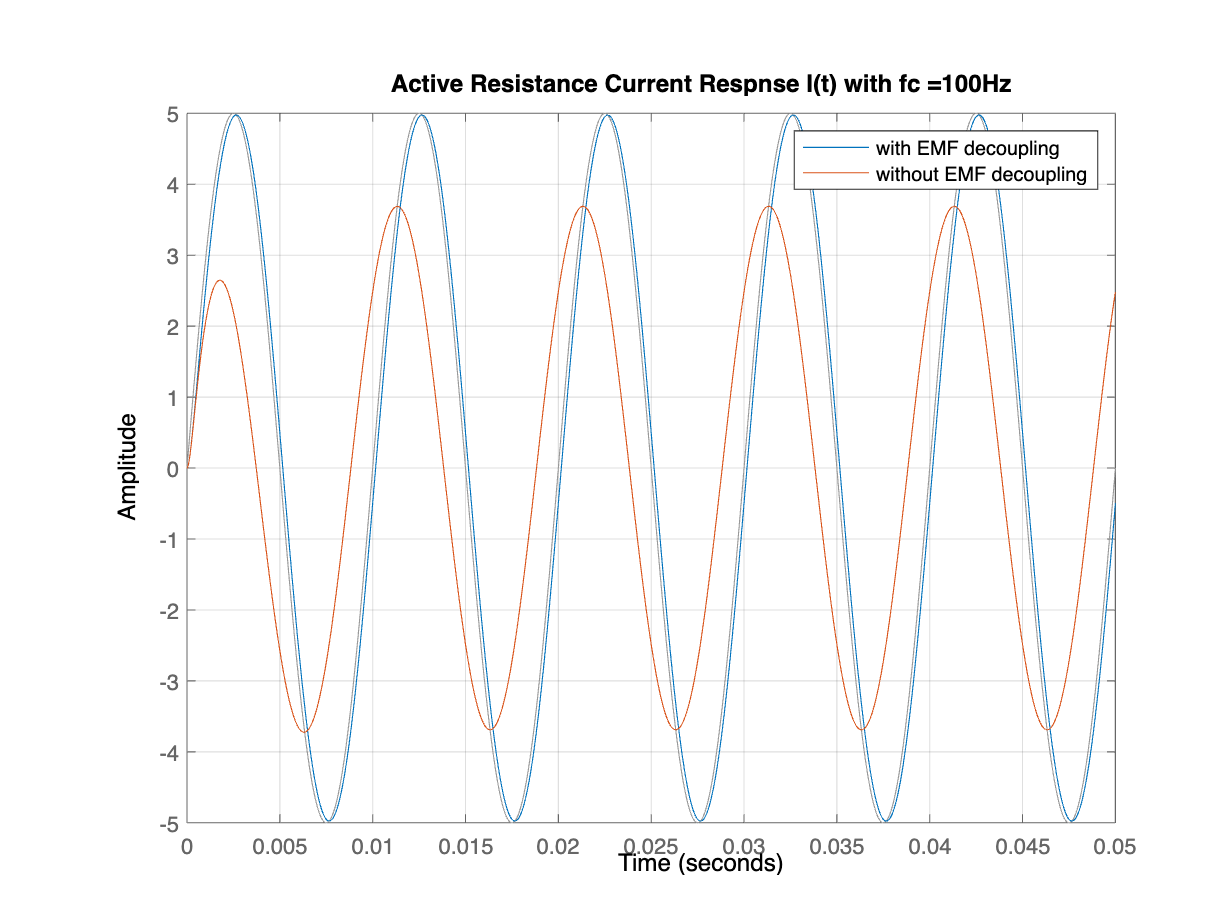

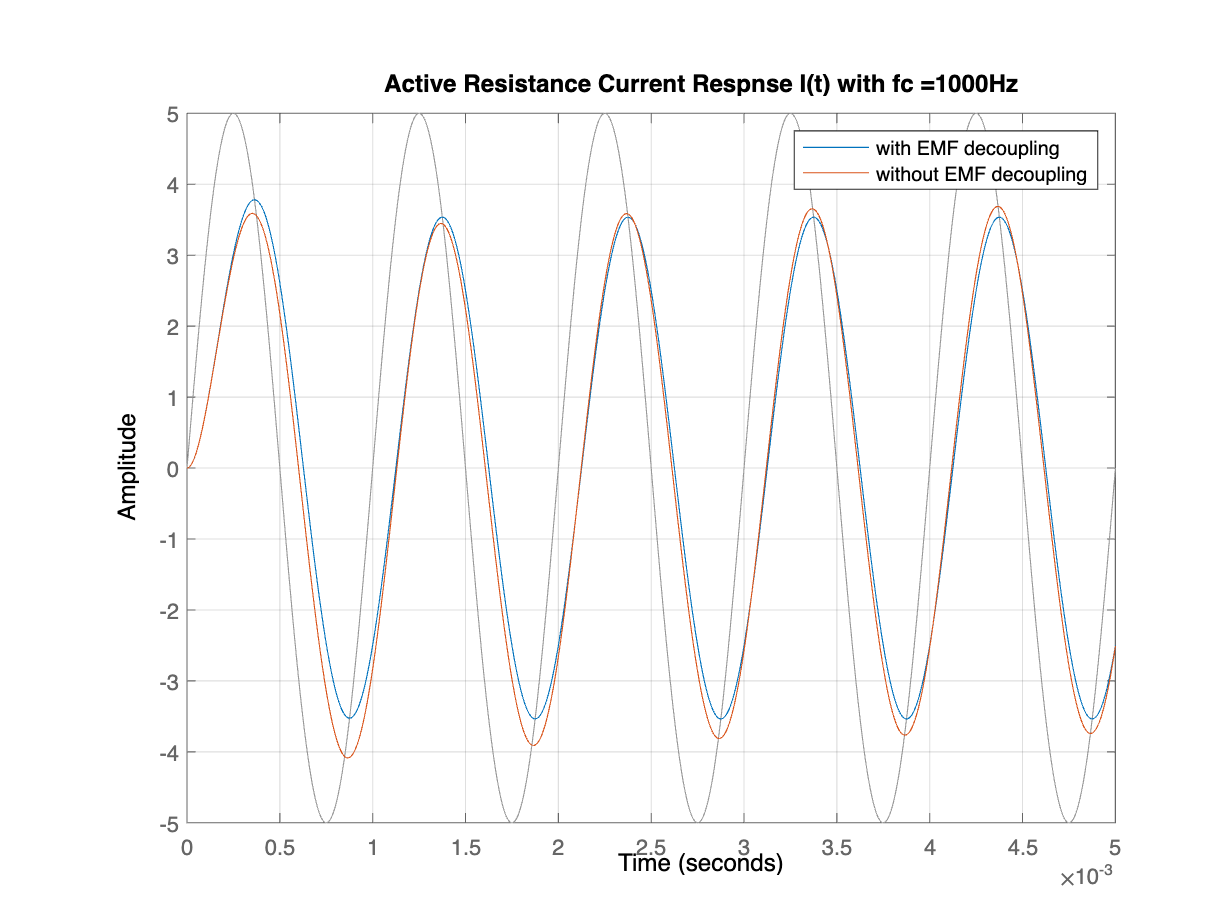

for f_c = [100, 1000]
    % with EMF decoupling
    K_hat_e = 0.2;
    EQ2_tf1 = subs(EQ2_2);
    tf1 = syms2tf(simplify(rhs(EQ2_tf1)));
    
    % without EMF decoupling
    K_hat_e = 0;
    EQ2_tf2 = subs(EQ2_2);
    tf2 = syms2tf(simplify(rhs(EQ2_tf2)));

    t = 0:(0.001/f_c):(5/f_c);
    i_ast_t = I_0 * sin(2*pi*f_c*t);
    
    figure
    lsim(tf1,tf2, i_ast_t,t);
    legend('with EMF decoupling', 'without EMF decoupling')
    grid on
    title(['Active Resistance Current Respnse I(t) with fc =',num2str(f_c),'Hz'])
    drawnow
end